% === LE + TE Morphing Geometry Comparison ==================================
% Wang et al. (2023), Kan et al. (2020), Wen et al. (2024)
% + standard RBF morphing using a Wendland C^2 radial basis function.
%
% PURPOSE
%   1) Reproduce the existing LE comparison.
%   2) Extend the SAME geometric analysis to the TE section.
%   3) Add a standard RBF-based morphing method to BOTH LE and TE.
%   4) Compare bounded segment area and camber-line curve length.
%   5) Verify the recovered hinge-to-tip deflection angle for every method.
%   6) Interactively regenerate a selected morphing configuration and export
%      its surface as two-column x-y coordinates.
%
% RBF METHOD / REFERENCES
%   The RBF displacement interpolation used here is
%
%       d(x) = sum_i lambda_i phi(||x-x_i||/R) + beta_0 + beta_x x + beta_y y
%
%   with the compact Wendland C^2 kernel
%
%       phi(r) = (1-r)^4 (4r+1),  0 <= r <= 1
%              = 0,              r > 1.
%
%   The polynomial augmentation is included so rigid translations/rotations
%   can be reproduced by the RBF coupling, following the standard augmented
%   RBF formulation used for aerodynamic shape/mesh interpolation.
%
%   RBF references:
%   [R1] A. de Boer, M.S. van der Schoot, H. Bijl,
%        "Mesh deformation based on radial basis function interpolation",
%        Computers & Structures, 85 (2007) 784-795.
%        DOI: 10.1016/j.compstruc.2007.01.013
%
%   [R2] J.H.S. Fincham, M.I. Friswell,
%        "Aerodynamic optimisation of a camber morphing aerofoil",
%        Aerospace Science and Technology, 43 (2015) 245-255.
%        DOI: 10.1016/j.ast.2015.02.023
%
%   Fincham & Friswell use Wendland C^2 RBF coupling for aerofoil shape
%   changes. In the present comparison, the RBF interpolation is driven by a
%   smooth Hermite-style x-y target. The prescribed target is constructed so
%   that the morphing junction has zero displacement and zero slope, while the
%   free end reaches the requested deflection angle with the correct chordwise
%   shortening and with a local tangent equal to the requested angle.
%
% IMPORTANT:
%   RBF is an interpolation framework, not a unique physical morphing law.
%   Therefore, a sparse set of surface-control motions must be prescribed.
%   Here the controls are generated from the smooth x-y target and the RBF
%   transfers those control-point displacements to the full aerofoil surface.
%   The non-morphing portion is explicitly kept fixed.
%
% IMPORTANT INTERPRETATION OF THE TE COMPARISON
%   - Wang et al. explicitly supports both LE and TE parabolic morphing.
%   - Kan et al. (2020) is an LE formulation. Its TE form below is a mirrored
%     geometric extension about x_TE/c.
%   - Wen et al. (2024) is an LE formulation and its fitted F_t polynomial is
%     tied to p/c = 0.15. For the TE comparison, the local TE coordinate is
%     mirrored and ISOTROPICALLY scaled onto the original p/c = 0.15 fitting
%     domain, morphed there, and scaled back. This preserves the requested
%     hinge-to-tip angle but should be described as an extension, not as an
%     original Wen TE formulation.
%
% NACA0012 NOTE
%   e = -0.1015 gives the open trailing edge used in the paper formulation.
%   To force a closed trailing edge, set naca_e = -0.1036 below.
%
% TE PLOTTING NOTE
%   The geometry remains mathematically OPEN at the trailing edge. For visual
%   comparison only, a short line is drawn between the upper and lower TE
%   endpoints of each plotted geometry. This line is NOT used by the morphing
%   formulation, area calculation, or curve-length calculation.
%
% MATLAB / LIVE SCRIPT NOTE
%   All executable script statements are above the local functions so this
%   can be pasted directly into a MATLAB Live Script or saved as an .m file.

clear; close all; clc;

%% ================= GLOBAL LATEX SETTINGS =================
set(groot, ...
    'defaultTextInterpreter'          , 'latex', ...
    'defaultAxesTickLabelInterpreter' , 'latex', ...
    'defaultLegendInterpreter'        , 'latex' );

%% ================= STYLE =================
FS.ax    = 12;
FS.lab   = 12;
FS.title = 12;
FS.leg   = 12;
FS.ann   = 12;
FS.lw    = 1.0;
FS.mlw   = 1.0;

figW_line = 2.75 * 1.5;
figH_line = 1.70 * 1.5;
figPos    = [0.5 0.5 figW_line figH_line];
axPosAll  = [0.17 0.20 0.68 0.70];

% ---------------- Colors ----------------
colKan  = [0.00 0.50 0.00];
colWang = [0.00 0.00 0.85];
colWen  = [0.85 0.00 0.85];
colRBF  = [0.90 0.45 0.00];
colBase = [0.00 0.00 0.00];

%% ================= USER INPUTS ============================================
c = 1.0;                 % chord [m]
tmax = 0.12;             % NACA0012 thickness ratio

% NACA trailing-edge coefficient
naca_e = -0.1015;        % OPEN trailing edge (paper formulation)
% naca_e = -0.1036;      % CLOSED trailing edge alternative

% Visual TE end-face connector ONLY (does not alter the open-TE geometry)
draw_TE_blunt_line = true;
TE_blunt_line_width = 0.8;

% Interactive x-y coordinate exporter shown after the analysis has finished.
% Set false if you do not want the UI to appear every time the script runs.
run_coordinate_export_ui = true;

% Leading-edge comparison
xLE_frac   = 0.15;       % LE morphing ends here: x_LE/c
amp_LE_deg = 30;         % requested LE morph angle [deg]

% Trailing-edge comparison
xTE_frac   = 0.75;       % TE morphing starts here: x_TE/c
amp_TE_deg = 30;         % requested TE morph angle [deg]

% RBF comparison settings
% Fincham & Friswell used a support radius just larger than the aerofoil
% chord. Because all coordinates below are normalized by c, R/c = 1.05 is
% used here. Increase/decrease this value to study RBF global/local influence.
rbf_support_radius = 1.05;   % R/c
rbf_n_active_ctrl  = 11;     % surface-control stations in the active segment
rbf_clip_stationary = true;  % enforce the non-morphing surface exactly fixed

if rbf_n_active_ctrl < 3
    error('rbf_n_active_ctrl must be at least 3.');
end
if rbf_support_radius <= 0
    error('rbf_support_radius must be positive.');
end

% Wen paper reference values
c_ref       = 0.15;      % paper chord [m]
pbar_ref    = 0.15;      % Wen fit is for p/c = 0.15
Kstar_paper = 26.43423;  %#ok<NASGU> % quoted paper value, retained for reference
amp_max_wen = 30;        % calibrate a = +1 to exactly +30 deg

%% ================= DISCRETIZATION ========================================
% N controls the background point count. The exact LE and TE junctions are
% explicitly inserted so area/length metrics are not biased by a grid point
% falling slightly to one side of x_LE or x_TE.
N = 5000;
xb = linspace(0,1,N);
xb = unique(sort([xb, xLE_frac, xTE_frac]));

% naca0012_half_thickness returns HALF-thickness y_t/c.
yt_b = naca0012_half_thickness(xb, tmax, naca_e);

xLE = xLE_frac;
xTE = xTE_frac;
LTE = 1 - xTE;

if xLE <= 0 || xLE >= 1
    error('xLE_frac must lie strictly between 0 and 1.');
end
if xTE <= 0 || xTE >= 1
    error('xTE_frac must lie strictly between 0 and 1.');
end
if xTE <= xLE
    error('For this LE + TE comparison, xTE_frac must be greater than xLE_frac.');
end

%% ================= WEN CALIBRATION =======================================
% Convert/recalibrate the Wen F_t fit in normalized form.
% The original supplied implementation calibrates Kbar so that a = +1 gives
% exactly 30 deg for the LE hinge-to-tip angle.
Ft0_a1   = Ft_poly_bar_from_paper(0, 1, c_ref);
Kbar_wen = tand(amp_max_wen) / (pbar_ref - Ft0_a1);

% Solve independent actuation commands for LE=30 deg and TE=12 deg.
a_cmd_LE = solve_a_for_target_angle(amp_LE_deg, pbar_ref, Kbar_wen, c_ref);
a_cmd_TE = solve_a_for_target_angle(amp_TE_deg, pbar_ref, Kbar_wen, c_ref);

%% ========================================================================
%% ======================= PART A: LE MORPHING =============================
%% ========================================================================

phi_LE   = deg2rad(amp_LE_deg);
delta_LE = phi_LE;

%% -------------------- A1) Wang LE ----------------------------------------
xc_wang_LE_b = xb;
yc_wang_LE_b = zeros(size(xb));

maskLE_W = xb < xLE;
D_LE = wang_parabolic_denom(delta_LE);

sLE = (xLE - xb(maskLE_W)) / xLE;   % 0 at hinge, 1 at nose
xi_LE  = (2*xLE/D_LE) .* sLE;
eta_LE = -(2*xLE/D_LE) .* sLE.^2 .* tan(delta_LE);

xc_wang_LE_b(maskLE_W) = xLE - xi_LE;
yc_wang_LE_b(maskLE_W) = eta_LE;

slope_wang_LE = gradient(yc_wang_LE_b, xc_wang_LE_b);
theta_wang_LE = atan(slope_wang_LE);

[xU_wang_LE_b, yU_wang_LE_b, xL_wang_LE_b, yL_wang_LE_b] = ...
    offset_half_thickness(xc_wang_LE_b, yc_wang_LE_b, yt_b, theta_wang_LE);

%% -------------------- A2) Kan LE -----------------------------------------
% Equivalent to the supplied Kan implementation for an initially straight
% NACA0012 camber line and one-step deflection from 0 to phi_LE.
xc_kan_LE_b = xb;
yc_kan_LE_b = zeros(size(xb));

maskLE_K = xb <= xLE;
sLE_K = xLE - xb(maskLE_K);

xc_kan_LE_b(maskLE_K) = xLE - cos(phi_LE).*sLE_K;
yc_kan_LE_b(maskLE_K) = -(sin(phi_LE)/xLE).*sLE_K.^2;

slope_kan_LE = gradient(yc_kan_LE_b, xc_kan_LE_b);
theta_kan_LE = atan(slope_kan_LE);

[xU_kan_LE_b, yU_kan_LE_b, xL_kan_LE_b, yL_kan_LE_b] = ...
    offset_half_thickness(xc_kan_LE_b, yc_kan_LE_b, yt_b, theta_kan_LE);

%% -------------------- A3) Wen / F_t LE -----------------------------------
xc_wen_LE_b = zeros(size(xb));
yc_wen_LE_b = zeros(size(xb));
xU_wen_LE_b = zeros(size(xb));
yU_wen_LE_b = zeros(size(xb));
xL_wen_LE_b = zeros(size(xb));
yL_wen_LE_b = zeros(size(xb));

for i = 1:numel(xb)
    [xc_wen_LE_b(i), yc_wen_LE_b(i)] = ...
        morph_surface_point_bar(xb(i), 0, a_cmd_LE, xLE, Kbar_wen, c_ref);

    [xU_wen_LE_b(i), yU_wen_LE_b(i)] = ...
        morph_surface_point_bar(xb(i), +yt_b(i), a_cmd_LE, xLE, Kbar_wen, c_ref);

    [xL_wen_LE_b(i), yL_wen_LE_b(i)] = ...
        morph_surface_point_bar(xb(i), -yt_b(i), a_cmd_LE, xLE, Kbar_wen, c_ref);
end

%% -------------------- A4) RBF LE: Wendland C^2 ----------------------------
% Standard RBF displacement coupling applied to sparse surface-control points.
% The control-point target prescribes BOTH x- and y-displacement using a smooth
% Hermite-style law. The LE target is the geometric mirror of the TE target.
% It has zero slope at x_LE and reaches the requested free-end position and
% local tangent angle at the nose.
[xU_rbf_LE_b, yU_rbf_LE_b, xL_rbf_LE_b, yL_rbf_LE_b, ...
 xc_rbf_LE_b, yc_rbf_LE_b, rbfInfo_LE] = ...
    rbf_morph_airfoil_segment(xb, yt_b, xLE, amp_LE_deg, 'LE', ...
                              rbf_n_active_ctrl, rbf_support_radius, ...
                              rbf_clip_stationary);

%% ========================================================================
%% ======================= PART B: TE MORPHING =============================
%% ========================================================================

phi_TE   = deg2rad(amp_TE_deg);
delta_TE = phi_TE;

%% -------------------- B1) Wang TE ----------------------------------------
% Wang-style TE parabolic morphing: mirrored spatial direction relative to
% the LE expression, with the TE segment length L_TE = 1 - x_TE.
%
% Positive amp_TE_deg is plotted here as DOWNWARD TE deflection.
xc_wang_TE_b = xb;
yc_wang_TE_b = zeros(size(xb));

maskTE_W = xb > xTE;
D_TE = wang_parabolic_denom(delta_TE);

sTE = (xb(maskTE_W) - xTE) / LTE;   % 0 at hinge, 1 at trailing edge
xi_TE  = (2*LTE/D_TE) .* sTE;
eta_TE = -(2*LTE/D_TE) .* sTE.^2 .* tan(delta_TE);

xc_wang_TE_b(maskTE_W) = xTE + xi_TE;
yc_wang_TE_b(maskTE_W) = eta_TE;

slope_wang_TE = gradient(yc_wang_TE_b, xc_wang_TE_b);
theta_wang_TE = atan(slope_wang_TE);

[xU_wang_TE_b, yU_wang_TE_b, xL_wang_TE_b, yL_wang_TE_b] = ...
    offset_half_thickness(xc_wang_TE_b, yc_wang_TE_b, yt_b, theta_wang_TE);

%% -------------------- B2) Kan TE: mirrored extension ---------------------
% Kan (2020) is an LE method. This is the exact geometric mirror of the
% supplied LE relation about x_TE, applied over x_TE <= x/c <= 1.
xc_kan_TE_b = xb;
yc_kan_TE_b = zeros(size(xb));

maskTE_K = xb >= xTE;
sTE_K = xb(maskTE_K) - xTE;

xc_kan_TE_b(maskTE_K) = xTE + cos(phi_TE).*sTE_K;
yc_kan_TE_b(maskTE_K) = -(sin(phi_TE)/LTE).*sTE_K.^2;

slope_kan_TE = gradient(yc_kan_TE_b, xc_kan_TE_b);
theta_kan_TE = atan(slope_kan_TE);

[xU_kan_TE_b, yU_kan_TE_b, xL_kan_TE_b, yL_kan_TE_b] = ...
    offset_half_thickness(xc_kan_TE_b, yc_kan_TE_b, yt_b, theta_kan_TE);

%% -------------------- B3) Wen / F_t TE: scaled mirrored extension --------
% Wen's F_t fit is LE-specific and fitted over p/c = 0.15. To compare its
% geometric behaviour over the TE segment x_TE -> 1 without pretending the
% paper supplied a TE law:
%   q = 1 - x                      (mirror x about the trailing edge)
%   q_fit = (pbar_ref/L_TE) q      (map TE segment onto fitted LE domain)
%   y_fit = (pbar_ref/L_TE) y      (same scale in y => preserves angles)
% After morphing, the result is scaled back and mirrored to physical x.
xc_wen_TE_b = zeros(size(xb));
yc_wen_TE_b = zeros(size(xb));
xU_wen_TE_b = zeros(size(xb));
yU_wen_TE_b = zeros(size(xb));
xL_wen_TE_b = zeros(size(xb));
yL_wen_TE_b = zeros(size(xb));

for i = 1:numel(xb)
    [xc_wen_TE_b(i), yc_wen_TE_b(i)] = ...
        morph_surface_point_TE_wen_scaled(xb(i), 0, a_cmd_TE, ...
                                         xTE, pbar_ref, Kbar_wen, c_ref);

    [xU_wen_TE_b(i), yU_wen_TE_b(i)] = ...
        morph_surface_point_TE_wen_scaled(xb(i), +yt_b(i), a_cmd_TE, ...
                                         xTE, pbar_ref, Kbar_wen, c_ref);

    [xL_wen_TE_b(i), yL_wen_TE_b(i)] = ...
        morph_surface_point_TE_wen_scaled(xb(i), -yt_b(i), a_cmd_TE, ...
                                         xTE, pbar_ref, Kbar_wen, c_ref);
end

%% -------------------- B4) RBF TE: Wendland C^2 ----------------------------
% Wendland C^2 RBF surface coupling driven by a smooth Hermite-style x-y
% target. The target provides chordwise shortening, zero slope at x_TE, and
% both a hinge-to-tip angle and a local trailing-edge tangent equal to
% amp_TE_deg.
[xU_rbf_TE_b, yU_rbf_TE_b, xL_rbf_TE_b, yL_rbf_TE_b, ...
 xc_rbf_TE_b, yc_rbf_TE_b, rbfInfo_TE] = ...
    rbf_morph_airfoil_segment(xb, yt_b, xTE, amp_TE_deg, 'TE', ...
                              rbf_n_active_ctrl, rbf_support_radius, ...
                              rbf_clip_stationary);

%% ================= CONVERT TO DIMENSIONAL FOR METRICS ====================
x  = c * xb;
yt = c * yt_b;

% LE
xc_wang_LE = c*xc_wang_LE_b; yc_wang_LE = c*yc_wang_LE_b;
xU_wang_LE = c*xU_wang_LE_b; yU_wang_LE = c*yU_wang_LE_b;
xL_wang_LE = c*xL_wang_LE_b; yL_wang_LE = c*yL_wang_LE_b;

xc_kan_LE = c*xc_kan_LE_b; yc_kan_LE = c*yc_kan_LE_b;
xU_kan_LE = c*xU_kan_LE_b; yU_kan_LE = c*yU_kan_LE_b;
xL_kan_LE = c*xL_kan_LE_b; yL_kan_LE = c*yL_kan_LE_b;

xc_wen_LE = c*xc_wen_LE_b; yc_wen_LE = c*yc_wen_LE_b;
xU_wen_LE = c*xU_wen_LE_b; yU_wen_LE = c*yU_wen_LE_b;
xL_wen_LE = c*xL_wen_LE_b; yL_wen_LE = c*yL_wen_LE_b;

xc_rbf_LE = c*xc_rbf_LE_b; yc_rbf_LE = c*yc_rbf_LE_b;
xU_rbf_LE = c*xU_rbf_LE_b; yU_rbf_LE = c*yU_rbf_LE_b;
xL_rbf_LE = c*xL_rbf_LE_b; yL_rbf_LE = c*yL_rbf_LE_b;

% TE
xc_wang_TE = c*xc_wang_TE_b; yc_wang_TE = c*yc_wang_TE_b;
xU_wang_TE = c*xU_wang_TE_b; yU_wang_TE = c*yU_wang_TE_b;
xL_wang_TE = c*xL_wang_TE_b; yL_wang_TE = c*yL_wang_TE_b;

xc_kan_TE = c*xc_kan_TE_b; yc_kan_TE = c*yc_kan_TE_b;
xU_kan_TE = c*xU_kan_TE_b; yU_kan_TE = c*yU_kan_TE_b;
xL_kan_TE = c*xL_kan_TE_b; yL_kan_TE = c*yL_kan_TE_b;

xc_wen_TE = c*xc_wen_TE_b; yc_wen_TE = c*yc_wen_TE_b;
xU_wen_TE = c*xU_wen_TE_b; yU_wen_TE = c*yU_wen_TE_b;
xL_wen_TE = c*xL_wen_TE_b; yL_wen_TE = c*yL_wen_TE_b;

xc_rbf_TE = c*xc_rbf_TE_b; yc_rbf_TE = c*yc_rbf_TE_b;
xU_rbf_TE = c*xU_rbf_TE_b; yU_rbf_TE = c*yU_rbf_TE_b;
xL_rbf_TE = c*xL_rbf_TE_b; yL_rbf_TE = c*yL_rbf_TE_b;

xLE_dim = xLE*c;
xTE_dim = xTE*c;

%% ========================================================================
%% ============================== LE FIGURE ================================
%% ========================================================================
figLE = figure('Color','w', ...
    'Units','inches', ...
    'Position', figPos, ...
    'PaperPositionMode','manual', ...
    'Name','LE_Morph_Comparison');

axLE = axes('Parent', figLE, 'Position', axPosAll);
hold(axLE,'on');
axis(axLE,'equal');

% Baseline
hBaseLE = plot(axLE, xb, +yt_b, '-.', ...
    'Color', colBase, 'LineWidth', 1.0, 'DisplayName', 'NACA0012');
plot(axLE, xb, -yt_b, '-.', ...
    'Color', colBase, 'LineWidth', 1.0, 'HandleVisibility','off');

% Kan
hKanLE = plot(axLE, xU_kan_LE_b, yU_kan_LE_b, '-', ...
    'Color', colKan, 'LineWidth', 0.5, 'DisplayName', 'Kan et al. (2020)');
plot(axLE, xL_kan_LE_b, yL_kan_LE_b, '-', ...
    'Color', colKan, 'LineWidth', 0.5, 'HandleVisibility','off');
plot(axLE, xc_kan_LE_b, yc_kan_LE_b, '--', ...
    'Color', colKan, 'LineWidth', 0.8, 'HandleVisibility','off');

% Wang
hWangLE = plot(axLE, xU_wang_LE_b, yU_wang_LE_b, '-', ...
    'Color', colWang, 'LineWidth', 0.5, 'DisplayName', 'Wang et al. (2023)');
plot(axLE, xL_wang_LE_b, yL_wang_LE_b, '-', ...
    'Color', colWang, 'LineWidth', 0.5, 'HandleVisibility','off');
plot(axLE, xc_wang_LE_b, yc_wang_LE_b, '--', ...
    'Color', colWang, 'LineWidth', 0.5, 'HandleVisibility','off');

% Wen
hWenLE = plot(axLE, xU_wen_LE_b, yU_wen_LE_b, '-', ...
    'Color', colWen, 'LineWidth', 0.5, 'DisplayName', 'Wen et al. (2024)');
plot(axLE, xL_wen_LE_b, yL_wen_LE_b, '-', ...
    'Color', colWen, 'LineWidth', 0.5, 'HandleVisibility','off');
plot(axLE, xc_wen_LE_b, yc_wen_LE_b, '--', ...
    'Color', colWen, 'LineWidth', 0.5, 'HandleVisibility','off');

% RBF / Wendland C^2
hRBFLE = plot(axLE, xU_rbf_LE_b, yU_rbf_LE_b, '-', ...
    'Color', colRBF, 'LineWidth', 0.7, 'DisplayName', 'RBF (Wendland $C^2$)');
plot(axLE, xL_rbf_LE_b, yL_rbf_LE_b, '-', ...
    'Color', colRBF, 'LineWidth', 0.7, 'HandleVisibility','off');
plot(axLE, xc_rbf_LE_b, yc_rbf_LE_b, '--', ...
    'Color', colRBF, 'LineWidth', 0.7, 'HandleVisibility','off');

xline(axLE, xLE, '--', '$x_{LE}$', ...
    'Interpreter','latex', ...
    'LabelVerticalAlignment','bottom', ...
    'HandleVisibility','off', ...
    'FontSize', FS.ax);

xline(axLE, 0, '--', 'HandleVisibility','off');
yline(axLE, 0, '--', '$y_{LE}$', ...
    'Interpreter','latex', ...
    'LabelHorizontalAlignment','right', ...
    'LabelVerticalAlignment','top', ...
    'HandleVisibility','off', ...
    'FontSize', FS.ax);

text(axLE, -0.050, -0.08, sprintf('$\\delta_{LE}^{max} = %.0f^\\circ$', amp_LE_deg), ...
    'Interpreter','latex', ...
    'FontSize', FS.ann, ...
    'Color','k', ...
    'HorizontalAlignment','center');

xlabel(axLE,'$x/c$', 'Interpreter','latex', 'FontSize', FS.lab);
ylabel(axLE,'$y/c$', 'Interpreter','latex', 'FontSize', FS.lab);

xlim(axLE, [-0.1 0.19]);
ylim(axLE, [-0.1 0.08]);
grid(axLE,'on'); box(axLE,'on');

set(axLE, ...
    'FontSize', FS.ax, ...
    'LineWidth', 1.0, ...
    'TickDir', 'out', ...
    'Layer', 'top');

lgdLE = legend(axLE, [hBaseLE, hKanLE, hWangLE, hWenLE, hRBFLE], ...
    {'NACA0012', 'Kan et al. (2020)', 'Wang et al. (2023)', ...
     'Wen et al. (2024)', 'RBF (Wendland $C^2$)'}, ...
    'Box','off', ...
    'Color','none', ...
    'FontSize', FS.leg, ...
    'Interpreter','latex', ...
    'Location','northwest');
lgdLE.ItemTokenSize = [10, 8];

setFigurePaper(figLE, figW_line, figH_line);
drawnow;

%% ========================================================================
%% ============================== TE FIGURE ================================
%% ========================================================================
figTE = figure('Color','w', ...
    'Units','inches', ...
    'Position', [5.0 0.5 figW_line figH_line], ...
    'PaperPositionMode','manual', ...
    'Name','TE_Morph_Comparison');

axTE = axes('Parent', figTE, 'Position', axPosAll);
hold(axTE,'on');
axis(axTE,'equal');

% Baseline
hBaseTE = plot(axTE, xb, +yt_b, '-.', ...
    'Color', colBase, 'LineWidth', 1.0, 'DisplayName', 'NACA0012');
plot(axTE, xb, -yt_b, '-.', ...
    'Color', colBase, 'LineWidth', 1.0, 'HandleVisibility','off');

% Visual blunt/open-TE end face: connect upper and lower end points only.
% This is plotting-only and does NOT modify the geometry or any metrics.
if draw_TE_blunt_line
    plot(axTE, [xb(end), xb(end)], [yt_b(end), -yt_b(end)], '-.', ...
        'Color', colBase, 'LineWidth', TE_blunt_line_width, ...
        'HandleVisibility','off');
end

% Kan mirrored extension
hKanTE = plot(axTE, xU_kan_TE_b, yU_kan_TE_b, '-', ...
    'Color', colKan, 'LineWidth', 0.5, 'DisplayName', 'Kan et al. (2020)');
plot(axTE, xL_kan_TE_b, yL_kan_TE_b, '-', ...
    'Color', colKan, 'LineWidth', 0.5, 'HandleVisibility','off');
if draw_TE_blunt_line
    plot(axTE, [xU_kan_TE_b(end), xL_kan_TE_b(end)], ...
               [yU_kan_TE_b(end), yL_kan_TE_b(end)], '-', ...
        'Color', colKan, 'LineWidth', TE_blunt_line_width, ...
        'HandleVisibility','off');
end
plot(axTE, xc_kan_TE_b, yc_kan_TE_b, '--', ...
    'Color', colKan, 'LineWidth', 0.8, 'HandleVisibility','off');

% Wang TE
hWangTE = plot(axTE, xU_wang_TE_b, yU_wang_TE_b, '-', ...
    'Color', colWang, 'LineWidth', 0.5, 'DisplayName', 'Wang et al. (2023)');
plot(axTE, xL_wang_TE_b, yL_wang_TE_b, '-', ...
    'Color', colWang, 'LineWidth', 0.5, 'HandleVisibility','off');
if draw_TE_blunt_line
    plot(axTE, [xU_wang_TE_b(end), xL_wang_TE_b(end)], ...
               [yU_wang_TE_b(end), yL_wang_TE_b(end)], '-', ...
        'Color', colWang, 'LineWidth', TE_blunt_line_width, ...
        'HandleVisibility','off');
end
plot(axTE, xc_wang_TE_b, yc_wang_TE_b, '--', ...
    'Color', colWang, 'LineWidth', 0.5, 'HandleVisibility','off');

% Wen scaled/mirrored extension
hWenTE = plot(axTE, xU_wen_TE_b, yU_wen_TE_b, '-', ...
    'Color', colWen, 'LineWidth', 0.5, 'DisplayName', 'Wen et al. (2024)');
plot(axTE, xL_wen_TE_b, yL_wen_TE_b, '-', ...
    'Color', colWen, 'LineWidth', 0.5, 'HandleVisibility','off');
if draw_TE_blunt_line
    plot(axTE, [xU_wen_TE_b(end), xL_wen_TE_b(end)], ...
               [yU_wen_TE_b(end), yL_wen_TE_b(end)], '-', ...
        'Color', colWen, 'LineWidth', TE_blunt_line_width, ...
        'HandleVisibility','off');
end
plot(axTE, xc_wen_TE_b, yc_wen_TE_b, '--', ...
    'Color', colWen, 'LineWidth', 0.5, 'HandleVisibility','off');

% RBF / Wendland C^2
hRBFTE = plot(axTE, xU_rbf_TE_b, yU_rbf_TE_b, '-', ...
    'Color', colRBF, 'LineWidth', 0.7, 'DisplayName', 'RBF (Wendland $C^2$)');
plot(axTE, xL_rbf_TE_b, yL_rbf_TE_b, '-', ...
    'Color', colRBF, 'LineWidth', 0.7, 'HandleVisibility','off');
if draw_TE_blunt_line
    plot(axTE, [xU_rbf_TE_b(end), xL_rbf_TE_b(end)], ...
               [yU_rbf_TE_b(end), yL_rbf_TE_b(end)], '-', ...
        'Color', colRBF, 'LineWidth', TE_blunt_line_width, ...
        'HandleVisibility','off');
end
plot(axTE, xc_rbf_TE_b, yc_rbf_TE_b, '--', ...
    'Color', colRBF, 'LineWidth', 0.7, 'HandleVisibility','off');

xline(axTE, xTE, '--', '$x_{TE}$', ...
    'Interpreter','latex', ...
    'LabelVerticalAlignment','bottom', ...
    'HandleVisibility','off', ...
    'FontSize', FS.ax);

xline(axTE, 1, '--', 'HandleVisibility','off');
yline(axTE, 0, '--', '$y_{TE}$', ...
    'Interpreter','latex', ...
    'LabelHorizontalAlignment','right', ...
    'LabelVerticalAlignment','top', ...
    'HandleVisibility','off', ...
    'FontSize', FS.ax);

text(axTE, 0.8, -0.067, sprintf('$\\delta_{TE}^{max} = %.0f^\\circ$', amp_TE_deg), ...
    'Interpreter','latex', ...
    'FontSize', FS.ann, ...
    'Color','k', ...
    'HorizontalAlignment','center');

xlabel(axTE,'$x/c$', 'Interpreter','latex', 'FontSize', FS.lab);
ylabel(axTE,'$y/c$', 'Interpreter','latex', 'FontSize', FS.lab);

xlim(axTE, [0.72 1.04]);
ylim(axTE, [-0.15 0.06]);
grid(axTE,'on'); box(axTE,'on');

set(axTE, ...
    'FontSize', FS.ax, ...
    'LineWidth', 1.0, ...
    'TickDir', 'out', ...
    'Layer', 'top');
lgdTE = legend(axTE, [hBaseTE, hKanTE, hWangTE, hWenTE, hRBFTE], ...
    {'NACA0012', 'Kan et al. (2020), mirrored', 'Wang et al. (2023)', ...
     'Wen et al. (2024), scaled/mirrored', 'RBF (Wendland $C^2$)'}, ...
    'Box','off', ...
    'Color','none', ...
    'FontSize', FS.leg, ...
    'Interpreter','latex', ...
    'Location','northwest');
lgdTE.ItemTokenSize = [10, 8];

setFigurePaper(figTE, figW_line, figH_line);
drawnow;

%% ========================================================================
%% ========================= GEOMETRIC METRICS =============================
%% ========================================================================

% ---------------- LE bounded area ----------------
A_LE_base = area_segment_polygon(x, +yt, x, -yt, x, 0, xLE_dim);
A_LE_wang = area_segment_polygon(xU_wang_LE, yU_wang_LE, ...
                                 xL_wang_LE, yL_wang_LE, x, 0, xLE_dim);
A_LE_kan  = area_segment_polygon(xU_kan_LE, yU_kan_LE, ...
                                 xL_kan_LE, yL_kan_LE, x, 0, xLE_dim);
A_LE_wen  = area_segment_polygon(xU_wen_LE, yU_wen_LE, ...
                                 xL_wen_LE, yL_wen_LE, x, 0, xLE_dim);
A_LE_rbf  = area_segment_polygon(xU_rbf_LE, yU_rbf_LE, ...
                                 xL_rbf_LE, yL_rbf_LE, x, 0, xLE_dim);

% ---------------- LE camber-line curve length ----------------
C_LE_base = effective_curve_length_segment(x, +yt, x, -yt, x, 0, xLE_dim);
C_LE_wang = effective_curve_length_segment(xU_wang_LE, yU_wang_LE, ...
                                            xL_wang_LE, yL_wang_LE, x, 0, xLE_dim);
C_LE_kan  = effective_curve_length_segment(xU_kan_LE, yU_kan_LE, ...
                                            xL_kan_LE, yL_kan_LE, x, 0, xLE_dim);
C_LE_wen  = effective_curve_length_segment(xU_wen_LE, yU_wen_LE, ...
                                            xL_wen_LE, yL_wen_LE, x, 0, xLE_dim);
C_LE_rbf  = effective_curve_length_segment(xU_rbf_LE, yU_rbf_LE, ...
                                            xL_rbf_LE, yL_rbf_LE, x, 0, xLE_dim);

% ---------------- TE bounded area ----------------
A_TE_base = area_segment_polygon(x, +yt, x, -yt, x, xTE_dim, c);
A_TE_wang = area_segment_polygon(xU_wang_TE, yU_wang_TE, ...
                                 xL_wang_TE, yL_wang_TE, x, xTE_dim, c);
A_TE_kan  = area_segment_polygon(xU_kan_TE, yU_kan_TE, ...
                                 xL_kan_TE, yL_kan_TE, x, xTE_dim, c);
A_TE_wen  = area_segment_polygon(xU_wen_TE, yU_wen_TE, ...
                                 xL_wen_TE, yL_wen_TE, x, xTE_dim, c);
A_TE_rbf  = area_segment_polygon(xU_rbf_TE, yU_rbf_TE, ...
                                 xL_rbf_TE, yL_rbf_TE, x, xTE_dim, c);

% ---------------- TE camber-line curve length ----------------
C_TE_base = effective_curve_length_segment(x, +yt, x, -yt, x, xTE_dim, c);
C_TE_wang = effective_curve_length_segment(xU_wang_TE, yU_wang_TE, ...
                                            xL_wang_TE, yL_wang_TE, x, xTE_dim, c);
C_TE_kan  = effective_curve_length_segment(xU_kan_TE, yU_kan_TE, ...
                                            xL_kan_TE, yL_kan_TE, x, xTE_dim, c);
C_TE_wen  = effective_curve_length_segment(xU_wen_TE, yU_wen_TE, ...
                                            xL_wen_TE, yL_wen_TE, x, xTE_dim, c);
C_TE_rbf  = effective_curve_length_segment(xU_rbf_TE, yU_rbf_TE, ...
                                            xL_rbf_TE, yL_rbf_TE, x, xTE_dim, c);

%% ====================== RECOVERED ANGLE CHECK ============================
% Hinge-to-free-end angle is the same deflection-angle definition used by
% the supplied LE implementations. TE downward angles are negative in the
% global x-y coordinate system, so magnitudes are reported as positive.

% LE: free end is the first point, hinge is xLE
ang_LE_wang = abs(atand(yc_wang_LE_b(1) / (xc_wang_LE_b(1) - xLE)));
ang_LE_kan  = abs(atand(yc_kan_LE_b(1)  / (xc_kan_LE_b(1)  - xLE)));
ang_LE_wen  = abs(atand(yc_wen_LE_b(1)  / (xc_wen_LE_b(1)  - xLE)));

% TE: free end is the last point, hinge is xTE
ang_TE_wang = abs(atand(yc_wang_TE_b(end) / (xc_wang_TE_b(end) - xTE)));
ang_TE_kan  = abs(atand(yc_kan_TE_b(end)  / (xc_kan_TE_b(end)  - xTE)));
ang_TE_wen  = abs(atand(yc_wen_TE_b(end)  / (xc_wen_TE_b(end)  - xTE)));

% RBF: use the geometric centreline recovered from the morphed upper/lower
% surfaces. xLE and xTE were inserted exactly into xb above.
[~, iLE_hinge] = min(abs(xb - xLE));
[~, iTE_hinge] = min(abs(xb - xTE));

ang_LE_rbf = abs(atand( ...
    (yc_rbf_LE_b(1) - yc_rbf_LE_b(iLE_hinge)) / ...
    (xc_rbf_LE_b(1) - xc_rbf_LE_b(iLE_hinge)) ));

ang_TE_rbf = abs(atand( ...
    (yc_rbf_TE_b(end) - yc_rbf_TE_b(iTE_hinge)) / ...
    (xc_rbf_TE_b(end) - xc_rbf_TE_b(iTE_hinge)) ));

%% ============================= TABLES ====================================
Method = ["Baseline"; "Wang"; "Kan"; "Wen/Ft"; "RBF/WendlandC2"];

LE_Area = [A_LE_base; A_LE_wang; A_LE_kan; A_LE_wen; A_LE_rbf];
LE_AreaChange_pct = 100*(LE_Area - A_LE_base)/A_LE_base;
LE_CurveLength = [C_LE_base; C_LE_wang; C_LE_kan; C_LE_wen; C_LE_rbf];
LE_CurveChange_pct = 100*(LE_CurveLength - C_LE_base)/C_LE_base;
LE_RecoveredAngle_deg = [0; ang_LE_wang; ang_LE_kan; ang_LE_wen; ang_LE_rbf];

LE_results = table(Method, LE_Area, LE_AreaChange_pct, ...
    LE_CurveLength, LE_CurveChange_pct, LE_RecoveredAngle_deg);

TE_Area = [A_TE_base; A_TE_wang; A_TE_kan; A_TE_wen; A_TE_rbf];
TE_AreaChange_pct = 100*(TE_Area - A_TE_base)/A_TE_base;
TE_CurveLength = [C_TE_base; C_TE_wang; C_TE_kan; C_TE_wen; C_TE_rbf];
TE_CurveChange_pct = 100*(TE_CurveLength - C_TE_base)/C_TE_base;
TE_RecoveredAngle_deg = [0; ang_TE_wang; ang_TE_kan; ang_TE_wen; ang_TE_rbf];

TE_results = table(Method, TE_Area, TE_AreaChange_pct, ...
    TE_CurveLength, TE_CurveChange_pct, TE_RecoveredAngle_deg);

%% ======================== REPORT TO COMMAND WINDOW =======================
fprintf('\n============================================================\n');

fprintf(' LE MORPHING GEOMETRIC COMPARISON\n');

 LE MORPHING GEOMETRIC COMPARISON


fprintf(' x_LE/c = %.4f, requested delta_LE = %.4f deg\n', xLE, amp_LE_deg);

 x_LE/c = 0.1500, requested delta_LE = 30.0000 deg


fprintf('============================================================\n');


fprintf('\n=== LE bounded segment area: 0 <= x/c <= %.4f ===\n', xLE);


=== LE bounded segment area: 0 <= x/c <= 0.1500 ===


fprintf('Baseline            : % .8e m^2\n', A_LE_base);

Baseline            :  1.16641249e-02 m^2


fprintf('Wang (parabolic)    : % .8e m^2  (Delta = %+9.5f %%)\n', A_LE_wang, LE_AreaChange_pct(2));

Wang (parabolic)    :  1.11842113e-02 m^2  (Delta =  -4.11444 %)


fprintf('Kan                 : % .8e m^2  (Delta = %+9.5f %%)\n', A_LE_kan,  LE_AreaChange_pct(3));

Kan                 :  1.15357359e-02 m^2  (Delta =  -1.10072 %)


fprintf('Wen/F_t             : % .8e m^2  (Delta = %+9.5f %%)\n', A_LE_wen,  LE_AreaChange_pct(4));

Wen/F_t             :  1.18559413e-02 m^2  (Delta =  +1.64450 %)


fprintf('RBF / Wendland C2   : % .8e m^2  (Delta = %+9.5f %%)\n', A_LE_rbf,  LE_AreaChange_pct(5));

RBF / Wendland C2   :  1.18018221e-02 m^2  (Delta =  +1.18052 %)



fprintf('\n=== LE camber-line curve length ===\n');


=== LE camber-line curve length ===


fprintf('Baseline            : % .8e m\n', C_LE_base);

Baseline            :  1.50000000e-01 m


fprintf('Wang (parabolic)    : % .8e m  (Delta = %+9.5f %%)\n', C_LE_wang, LE_CurveChange_pct(2));

Wang (parabolic)    :  1.49999992e-01 m  (Delta =  -0.00001 %)


fprintf('Kan                 : % .8e m  (Delta = %+9.5f %%)\n', C_LE_kan,  LE_CurveChange_pct(3));

Kan                 :  1.54714557e-01 m  (Delta =  +3.14304 %)


fprintf('Wen/F_t             : % .8e m  (Delta = %+9.5f %%)\n', C_LE_wen,  LE_CurveChange_pct(4));

Wen/F_t             :  1.52574170e-01 m  (Delta =  +1.71611 %)


fprintf('RBF / Wendland C2   : % .8e m  (Delta = %+9.5f %%)\n', C_LE_rbf,  LE_CurveChange_pct(5));

RBF / Wendland C2   :  1.52570058e-01 m  (Delta =  +1.71337 %)



fprintf('\n=== LE recovered hinge-to-tip angle ===\n');


=== LE recovered hinge-to-tip angle ===


fprintf('Requested           : %.12f deg\n', amp_LE_deg);

Requested           : 30.000000000000 deg


fprintf('Wang                : %.12f deg\n', ang_LE_wang);

Wang                : 30.000000000000 deg


fprintf('Kan                 : %.12f deg\n', ang_LE_kan);

Kan                 : 30.000000000000 deg


fprintf('Wen/F_t             : %.12f deg\n', ang_LE_wen);

Wen/F_t             : 30.000000000000 deg


fprintf('RBF / Wendland C2   : %.12f deg\n', ang_LE_rbf);

RBF / Wendland C2   : 30.000000000001 deg


fprintf('Wen solved a_cmd_LE : %.12f\n', a_cmd_LE);

Wen solved a_cmd_LE : 1.000000000000


fprintf('RBF control points  : %d\n', rbfInfo_LE.Ncontrol);

RBF control points  : 21


fprintf('RBF support R/c     : %.6f\n', rbfInfo_LE.supportRadius);

RBF support R/c     : 1.050000


fprintf('RBF cond(A)         : %.6e\n', rbfInfo_LE.condA);

RBF cond(A)         : 1.193252e+06


fprintf('RBF max ctrl error  : %.6e (normalized coordinates)\n', rbfInfo_LE.maxControlError);

RBF max ctrl error  : 5.402578e-15 (normalized coordinates)


fprintf('RBF leakage pre-clip: %.6e (max stationary-surface displacement)\n', ...
    rbfInfo_LE.maxStationaryLeakageBeforeClipping);

RBF leakage pre-clip: 1.916688e-01 (max stationary-surface displacement)


fprintf('RBF target tip |y|/c: %.6e\n', rbfInfo_LE.tipDeflection);

RBF target tip |y|/c: 7.500000e-02



fprintf('\n============================================================\n');

fprintf(' TE MORPHING GEOMETRIC COMPARISON\n');

 TE MORPHING GEOMETRIC COMPARISON


fprintf(' x_TE/c = %.4f, requested delta_TE = %.4f deg\n', xTE, amp_TE_deg);

 x_TE/c = 0.7500, requested delta_TE = 30.0000 deg


fprintf('============================================================\n');


fprintf('\n=== TE bounded segment area: %.4f <= x/c <= 1 ===\n', xTE);


=== TE bounded segment area: 0.7500 <= x/c <= 1 ===


fprintf('Baseline                    : % .8e m^2\n', A_TE_base);

Baseline                    :  8.58818745e-03 m^2


fprintf('Wang (parabolic TE)         : % .8e m^2  (Delta = %+9.5f %%)\n', A_TE_wang, TE_AreaChange_pct(2));

Wang (parabolic TE)         :  8.00411339e-03 m^2  (Delta =  -6.80090 %)


fprintf('Kan (mirrored extension)    : % .8e m^2  (Delta = %+9.5f %%)\n', A_TE_kan,  TE_AreaChange_pct(3));

Kan (mirrored extension)    :  8.25568618e-03 m^2  (Delta =  -3.87161 %)


fprintf('Wen/F_t (scaled + mirrored) : % .8e m^2  (Delta = %+9.5f %%)\n', A_TE_wen,  TE_AreaChange_pct(4));

Wen/F_t (scaled + mirrored) :  8.71861664e-03 m^2  (Delta =  +1.51870 %)


fprintf('RBF / Wendland C2           : % .8e m^2  (Delta = %+9.5f %%)\n', A_TE_rbf,  TE_AreaChange_pct(5));

RBF / Wendland C2           :  8.63466876e-03 m^2  (Delta =  +0.54122 %)



fprintf('\n=== TE camber-line curve length ===\n');


=== TE camber-line curve length ===


fprintf('Baseline                    : % .8e m\n', C_TE_base);

Baseline                    :  2.50000000e-01 m


fprintf('Wang (parabolic TE)         : % .8e m  (Delta = %+9.5f %%)\n', C_TE_wang, TE_CurveChange_pct(2));

Wang (parabolic TE)         :  2.49999995e-01 m  (Delta =  -0.00000 %)


fprintf('Kan (mirrored extension)    : % .8e m  (Delta = %+9.5f %%)\n', C_TE_kan,  TE_CurveChange_pct(3));

Kan (mirrored extension)    :  2.57857604e-01 m  (Delta =  +3.14304 %)


fprintf('Wen/F_t (scaled + mirrored) : % .8e m  (Delta = %+9.5f %%)\n', C_TE_wen,  TE_CurveChange_pct(4));

Wen/F_t (scaled + mirrored) :  2.54290293e-01 m  (Delta =  +1.71612 %)


fprintf('RBF / Wendland C2           : % .8e m  (Delta = %+9.5f %%)\n', C_TE_rbf,  TE_CurveChange_pct(5));

RBF / Wendland C2           :  2.54282479e-01 m  (Delta =  +1.71299 %)



fprintf('\n=== TE recovered hinge-to-tip angle ===\n');


=== TE recovered hinge-to-tip angle ===


fprintf('Requested           : %.12f deg\n', amp_TE_deg);

Requested           : 30.000000000000 deg


fprintf('Wang                : %.12f deg\n', ang_TE_wang);

Wang                : 30.000000000000 deg


fprintf('Kan mirrored        : %.12f deg\n', ang_TE_kan);

Kan mirrored        : 30.000000000000 deg


fprintf('Wen scaled/mirrored : %.12f deg\n', ang_TE_wen);

Wen scaled/mirrored : 30.000000000000 deg


fprintf('RBF / Wendland C2   : %.12f deg\n', ang_TE_rbf);

RBF / Wendland C2   : 29.999999999999 deg


fprintf('Wen solved a_cmd_TE : %.12f\n', a_cmd_TE);

Wen solved a_cmd_TE : 1.000000000000


fprintf('RBF control points  : %d\n', rbfInfo_TE.Ncontrol);

RBF control points  : 22


fprintf('RBF support R/c     : %.6f\n', rbfInfo_TE.supportRadius);

RBF support R/c     : 1.050000


fprintf('RBF cond(A)         : %.6e\n', rbfInfo_TE.condA);

RBF cond(A)         : 3.538607e+06


fprintf('RBF max ctrl error  : %.6e (normalized coordinates)\n', rbfInfo_TE.maxControlError);

RBF max ctrl error  : 3.916538e-15 (normalized coordinates)


fprintf('RBF leakage pre-clip: %.6e (max stationary-surface displacement)\n', ...
    rbfInfo_TE.maxStationaryLeakageBeforeClipping);

RBF leakage pre-clip: 2.005449e-01 (max stationary-surface displacement)


fprintf('RBF target tip |y|/c: %.6e\n', rbfInfo_TE.tipDeflection);

RBF target tip |y|/c: 1.250000e-01



fprintf('\nNOTE: Kan and Wen TE curves are extensions for geometric comparison;\n');


NOTE: Kan and Wen TE curves are extensions for geometric comparison;


fprintf('      they are not claimed as original TE formulations from those papers.\n');

      they are not claimed as original TE formulations from those papers.


fprintf('      The RBF curves use Wendland C2 displacement interpolation with a\n');

      The RBF curves use Wendland C2 displacement interpolation with a


fprintf('      smooth Hermite-style x-y target; the LE case mirrors the TE target.\n');

      smooth Hermite-style x-y target; the LE case mirrors the TE target.



fprintf('\n=== LE RESULTS TABLE ===\n');


=== LE RESULTS TABLE ===


disp(LE_results);

         Method         LE_Area     LE_AreaChange_pct    LE_CurveLength    LE_CurveChange_pct    LE_RecoveredAngle_deg
    ________________    ________    _________________    ______________    __________________    _____________________

    "Baseline"          0.011664               0               0.15                     0                  0          
    "Wang"              0.011184         -4.1144               0.15           -5.4284e-06                 30          
    "Kan"               0.011536         -1.1007            0.15471                 3.143                 30          
    "Wen/Ft"            0.011856          1.6445            0.15257                1.7161                 30          
    "RBF/WendlandC2"    0.011802          1.1805            0.15257              


fprintf('\n=== TE RESULTS TABLE ===\n');


=== TE RESULTS TABLE ===


disp(TE_results);

         Method          TE_Area     TE_AreaChange_pct    TE_CurveLength    TE_CurveChange_pct    TE_RecoveredAngle_deg
    ________________    _________    _________________    ______________    __________________    _____________________

    "Baseline"          0.0085882               0               0.25                     0                  0          
    "Wang"              0.0080041         -6.8009               0.25           -1.9544e-06                 30          
    "Kan"               0.0082557         -3.8716            0.25786                 3.143                 30          
    "Wen/Ft"            0.0087186          1.5187            0.25429                1.7161                 30          
    "RBF/WendlandC2"    0.0086347         0.54122            0.25428       

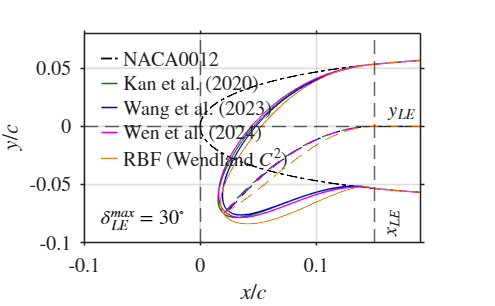


%% ============================= EXPORT ====================================
% Keep export statements BEFORE local functions so the script remains valid.



% True vector export
exportgraphics(figLE, sprintf('LE_Morph_Comparison_%gdeg.pdf', amp_LE_deg), ...
    'ContentType', 'vector');

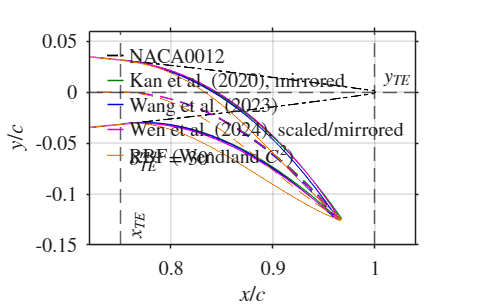

exportgraphics(figTE, sprintf('TE_Morph_Comparison_%gdeg.pdf', amp_TE_deg), ...
    'ContentType', 'vector');


 MORPHING X-Y COORDINATES GENERATED
LE enabled          : YES
LE model            : Wang (parabolic)
x_LE/c              : 0.15
LE angle            : 30 deg
TE enabled          : YES
TE model            : Wang (parabolic)
x_TE/c              : 0.75
TE angle            : 30 deg
Coordinate type     : NORMALIZED
Export scope        : FULL
Chord               : 1 m

--- SURFACE POINT SETTINGS ---
Upper/top requested : 301 points | Normal (uniform)
Lower/bottom req.   : 301 points | Normal (uniform)
Blunt TE enabled    : YES
Blunt TE requested  : 21 points | Normal (uniform)
Number of XY rows   : 621
Workspace variable  : XY_export
First up to 10 rows:
    0.9609   -0.1204
    0.9588   -0.1174
    0.9568   -0.1145
    0.9547   -0.1116
    0.9526   -0.1087
    0.9505   -0.1058
    0.9484   -0.1030
    0.9463   -0.1001
    0.9441   -0.0973
    0.9420   -0.0944

Saved coor

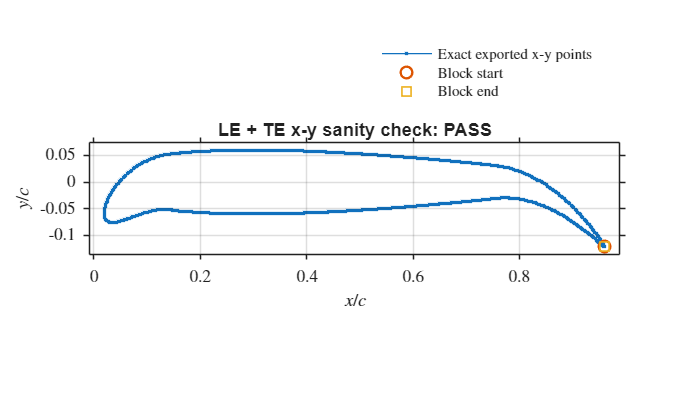


% If dense vector export crashes on your machine, comment the two lines above
% and use these fallbacks instead:
%
% exportgraphics(figLE, 'LE_Morph_Comparison.pdf', ...
%     'ContentType', 'image', 'Resolution', 600);
% exportgraphics(figTE, 'TE_Morph_Comparison_12deg.pdf', ...
%     'ContentType', 'image', 'Resolution', 600);

%% ========================================================================
%% ================= INTERACTIVE X-Y COORDINATE EXPORT =====================
%% ========================================================================
% This section does NOT simply dump the already plotted arrays.  It asks the
% user for a morphing configuration and regenerates that geometry using the
% same mathematical model/functions used above, then exports the selected
% surface as a clean two-column [x y] file.
%
% SINGLE-WINDOW UI choices (all visible together):
%   1) enable LE and/or TE morphing (both may be selected together)
%   2) independent LE and TE mathematical models
%   3) independent LE and TE hinge positions and deflection angles
%   4) normalized x/c,y/c or dimensional x,y [m]
%   5) full aerofoil or active morphing segment(s) only
%   6) optionally save the generated two-column coordinate file
%   7) independently choose point count/distribution for upper, lower, blunt
%   8) optionally plot the generated x-y coordinates for a sanity check
%
% Point distributions are applied by ARC LENGTH after morphing:
%   Normal = uniform; Sine = cluster at traversal end; Cosine = cluster at start.
%
% The output ordering follows the usual continuous aerofoil-surface order:
%   upper surface: TE -> LE
%   lower surface: LE -> TE
% For an active segment, the equivalent free-end/junction ordering is used.
% The optional Blunt TE export surface connects lower TE -> upper TE.  If it
% is disabled, the original mathematically open trailing edge remains open.
%
% The selected matrix remains in the workspace as XY_export even if the user
% cancels the final save dialog.

XY_export = [];
coordinate_export_info = struct();

if run_coordinate_export_ui
    exportCfg = struct();
    exportCfg.xb = xb;
    exportCfg.yt_b = yt_b;
    exportCfg.c = c;
    exportCfg.tmax = tmax;
    exportCfg.naca_e = naca_e;
    exportCfg.xLE = xLE;
    exportCfg.xTE = xTE;
    exportCfg.defaultLEAngle = amp_LE_deg;
    exportCfg.defaultTEAngle = amp_TE_deg;
    exportCfg.pbar_ref = pbar_ref;
    exportCfg.Kbar_wen = Kbar_wen;
    exportCfg.c_ref = c_ref;
    exportCfg.rbf_n_active_ctrl = rbf_n_active_ctrl;
    exportCfg.rbf_support_radius = rbf_support_radius;
    exportCfg.rbf_clip_stationary = rbf_clip_stationary;

    [XY_export, coordinate_export_info] = coordinate_export_ui(exportCfg);
end


%% ========================================================================
%% ============================ LOCAL FUNCTIONS ============================
%% ========================================================================

function yt = naca0012_half_thickness(x, t, eCoeff)
% NACA 00xx HALF-thickness distribution, returned as y_t/c.
% Open TE : eCoeff = -0.1015
% Closed TE: eCoeff = -0.1036
    yt = 5*t*( 0.2969*sqrt(max(x,0)) ...
             - 0.1260*x ...
             - 0.3516*x.^2 ...
             + 0.2843*x.^3 ...
             + eCoeff*x.^4 );
end

function D = wang_parabolic_denom(delta)
% Robust form of the denominator used in the Wang parabolic geometry.
% Limit as delta -> 0 is D -> 2.
    q = 2*tan(delta);
    if abs(q) < 1e-12
        D = 2;
    else
        D = sqrt(q^2 + 1) + asinh(q)/q;
    end
end

function [xU, yU, xL, yL] = offset_half_thickness(xc, yc, ytHalf, theta)
% Offset the half-thickness normal to the camber line.
% ytHalf is already half-thickness, hence there is NO additional /2 here.
    xU = xc - ytHalf .* sin(theta);
    yU = yc + ytHalf .* cos(theta);
    xL = xc + ytHalf .* sin(theta);
    yL = yc - ytHalf .* cos(theta);
end

function a_cmd = solve_a_for_target_angle(target_deg, pbar, Kbar, c_ref)
% Solve for a in [-1,1] so that the Wen hinge-to-tip angle equals target_deg.
    aa  = linspace(-1, 1, 4001);
    ang = arrayfun(@(a) wei_paper_angle_deg(a, pbar, Kbar, c_ref), aa);

    [minerr, imin] = min(abs(ang - target_deg));
    if minerr < 1e-10
        a_cmd = aa(imin);
        return;
    end

    f = ang - target_deg;
    idx = find(f(1:end-1).*f(2:end) < 0, 1, 'first');

    if isempty(idx)
        error(['Requested angle = %.6f deg is outside the feasible Wen/F_t range. ' ...
               'Approximate range over a in [-1,1] is [%.6f, %.6f] deg.'], ...
               target_deg, min(ang), max(ang));
    end

    aL = aa(idx);
    aR = aa(idx+1);
    rootfun = @(a) wei_paper_angle_deg(a, pbar, Kbar, c_ref) - target_deg;
    a_cmd = fzero(rootfun, [aL, aR]);
end

function sdeg = wei_paper_angle_deg(a, pbar, Kbar, c_ref)
% Wen/F_t hinge-to-tip LE angle in the same sign convention as the supplied
% Wang/Kan comparison.
    Ft0 = Ft_poly_bar_from_paper(0, a, c_ref);
    y0  = -Kbar * a * (Ft0 - pbar).^2;
    sdeg = atand(y0 / (Ft0 - pbar));
end

function [xs, ys] = morph_surface_point_bar(x0b, y0b, a, pbar, Kbar, c_ref)
% Wen LE morphing point in normalized coordinates.
    if x0b >= pbar || abs(a) < 1e-14 || abs(Kbar) < 1e-14
        xs = x0b;
        ys = y0b;
        return;
    end

    x1b   = Ft_poly_bar_from_paper(x0b, a, c_ref);
    ycam  = -Kbar * a * (x1b - pbar).^2;
    theta = -atan(2 * Kbar * a * (x1b - pbar));

    xs = x1b - y0b .* sin(theta);
    ys = ycam + y0b .* cos(theta);
end

function [xs, ys] = morph_surface_point_TE_wen_scaled(x0b, y0b, a, ...
                                                       xTE, pfit, Kbar, c_ref)
% TE extension of the Wen LE F_t mapping for GEOMETRIC COMPARISON ONLY.
%
% 1) Mirror the TE segment using q = 1-x.
% 2) Isotropically scale q and y so q in [0,L_TE] maps onto [0,pfit].
% 3) Apply the original Wen LE point mapping.
% 4) Scale back and mirror q back to x.
%
% Isotropic x-y scaling preserves the requested hinge-to-tip angle.
    if x0b <= xTE || abs(a) < 1e-14 || abs(Kbar) < 1e-14
        xs = x0b;
        ys = y0b;
        return;
    end

    LTE = 1 - xTE;
    if LTE <= 0
        error('xTE must be < 1.');
    end

    fitScale = pfit / LTE;

    q0     = 1 - x0b;
    q0_fit = fitScale * q0;
    y0_fit = fitScale * y0b;

    [qS_fit, yS_fit] = morph_surface_point_bar(q0_fit, y0_fit, ...
                                               a, pfit, Kbar, c_ref);

    qS = qS_fit / fitScale;
    ys = yS_fit / fitScale;
    xs = 1 - qS;
end

function Fbar = Ft_poly_bar_from_paper(xb, a, c_ref)
% Convert the Wen paper dimensional F_t(x) polynomial into normalized form:
% Fbar = F_t/c_ref with xb = x/c_ref.

    C00 = +2.201e-4;

    C10 = +0.0;      C11 = +0.9599;

    C20 = +3.128e-3; C21 = +0.0;     C22 = +2.100;

    C30 = +0.0;      C31 = -0.3062;  C32 = +0.0;     C33 = -16.35;

    C40 = -6.410e-5; C41 = +0.0;     C42 = +7.549;   C43 = +0.0;   C44 = -788.4;

    Fbar = 0 ...
        + C00/c_ref ...
        + (C10/c_ref*a + C11*xb) ...
        + (C20/c_ref*a.^2 + C21*a.*xb + C22*c_ref*xb.^2) ...
        + (C30/c_ref*a.^3 + C31*a.^2.*xb + C32*c_ref*a.*xb.^2 ...
           + C33*c_ref^2*xb.^3) ...
        + (C40/c_ref*a.^4 + C41*a.^3.*xb + C42*c_ref*a.^2.*xb.^2 ...
           + C43*c_ref^2*a.*xb.^3 + C44*c_ref^3*xb.^4);
end


function [xU_m, yU_m, xL_m, yL_m, xc_m, yc_m, info] = ...
    rbf_morph_airfoil_segment(xb, ytHalf, hinge, delta_deg, side, ...
                              nCtrl, supportRadius, clipStationary)
% RBF_MORPH_AIRFOIL_SEGMENT
% Morph an LE or TE surface segment using a standard augmented RBF
% displacement interpolation with a Wendland C^2 compact-support kernel.
%
% INPUTS
%   xb, ytHalf        : normalized baseline x/c and NACA half-thickness y_t/c
%   hinge             : x_LE/c for side='LE' or x_TE/c for side='TE'
%   delta_deg         : requested hinge-to-tip angle [deg]
%   side              : 'LE' or 'TE'
%   nCtrl             : number of x-stations used as active surface controls
%   supportRadius     : normalized RBF support radius R/c
%   clipStationary    : if true, the non-morphing segment is reset exactly
%                       to the baseline geometry after RBF interpolation
%
% METHOD
%   1) Create a smooth Hermite-style x-y target over the active segment.
%
%      q = 0 at the morphing junction and q = 1 at the free end.
%
%      G(q) = q + (1-cos(delta))*(q^3 - 2*q^2)
%      H(q) = 2*q^2 - q^3
%
%      TE:
%          xc = hinge + L*G(q)
%          yc = -L*sin(delta)*H(q)
%
%      LE:
%          xc = hinge - L*G(q)
%          yc = -L*sin(delta)*H(q)
%
%      This gives zero displacement gradient at the hinge in y, preserves
%      the intended free-end distance L, introduces the required x-shortening,
%      and makes the local free-end tangent exactly +/- delta.
%
%   2) Offset the original NACA half-thickness normal to that target camber
%      at sparse surface-control stations.
%
%   3) Interpolate the CONTROL-POINT DISPLACEMENTS to every aerodynamic
%      surface point using
%
%      d(x) = sum lambda_i phi(||x-x_i||/R) + beta_0 + beta_x x + beta_y y
%
%      phi(q) = (1-q)^4(4q+1), q <= 1; phi = 0 otherwise.
%
% The augmented polynomial constraints are P^T lambda = 0.
%
% This follows the standard RBF coupling structure used for aerodynamic
% shape interpolation. RBF is an interpolation framework, so the prescribed
% control motion is an explicit part of the definition of this comparison.

    xb = xb(:);
    ytHalf = ytHalf(:);

    side = upper(string(side));
    if side ~= "LE" && side ~= "TE"
        error('side must be ''LE'' or ''TE''.');
    end
    if nCtrl < 3
        error('nCtrl must be at least 3.');
    end
    if supportRadius <= 0
        error('supportRadius must be positive.');
    end

    if side == "LE"
        xCtrl = linspace(0, hinge, nCtrl).';
        active = xb <= hinge + 100*eps(max(1,abs(hinge)));
        stationary = ~active;
    else
        xCtrl = linspace(hinge, 1, nCtrl).';
        active = xb >= hinge - 100*eps(max(1,abs(hinge)));
        stationary = ~active;
    end

    % Baseline half-thickness at the sparse surface-control stations.
    ytCtrl = interp1(xb, ytHalf, xCtrl, 'linear');

    % Smooth x-y target camber and its local tangent angle.
    [xcTarget, ycTarget, thetaTarget, wTip] = ...
        rbf_smooth_camber_target(xCtrl, hinge, delta_deg, side);

    % Target upper/lower surface control points, with thickness offset normal
    % to the target camber line.
    [xU_target, yU_target, xL_target, yL_target] = ...
        offset_half_thickness(xcTarget, ycTarget, ytCtrl, thetaTarget);

    source = [xCtrl, +ytCtrl; ...
              xCtrl, -ytCtrl];

    target = [xU_target, yU_target; ...
              xL_target, yL_target];

    % The NACA leading-edge upper/lower control point is duplicated because
    % y_t=0 there. Remove exact duplicate source rows.
    [source, ia] = unique(source, 'rows', 'stable');
    target = target(ia,:);

    displacement = target - source;

    model = rbf_fit_wendland_c2(source, displacement, supportRadius);

    baseU = [xb, +ytHalf];
    baseL = [xb, -ytHalf];

    morphedU = rbf_apply_model(baseU, model);
    morphedL = rbf_apply_model(baseL, model);

    % Quantify any RBF leakage into the stationary surface before optional
    % exact clipping. This is useful when changing the support radius.
    if any(stationary)
        leakU = hypot(morphedU(stationary,1) - baseU(stationary,1), ...
                      morphedU(stationary,2) - baseU(stationary,2));
        leakL = hypot(morphedL(stationary,1) - baseL(stationary,1), ...
                      morphedL(stationary,2) - baseL(stationary,2));
        maxStationaryLeakage = max([leakU; leakL]);
    else
        maxStationaryLeakage = 0;
    end

    if clipStationary
        morphedU(stationary,:) = baseU(stationary,:);
        morphedL(stationary,:) = baseL(stationary,:);
    end

    % Geometric centreline used consistently for plotting and angle checks.
    centre = 0.5 * (morphedU + morphedL);

    % Exact interpolation error at the control points.
    targetRecovered = rbf_apply_model(source, model);
    ctrlErr = hypot(targetRecovered(:,1) - target(:,1), ...
                    targetRecovered(:,2) - target(:,2));

    xU_m = morphedU(:,1).';
    yU_m = morphedU(:,2).';
    xL_m = morphedL(:,1).';
    yL_m = morphedL(:,2).';
    xc_m = centre(:,1).';
    yc_m = centre(:,2).';

    info = struct();
    info.Ncontrol = size(source,1);
    info.supportRadius = supportRadius;
    info.condA = model.condA;
    info.rcondA = model.rcondA;
    info.maxControlError = max(ctrlErr);
    info.maxStationaryLeakageBeforeClipping = maxStationaryLeakage;
    info.tipDeflection = wTip;
    info.nActiveStations = nCtrl;
    info.clipStationary = logical(clipStationary);
end


function [xc, yc, theta, wTip] = ...
    rbf_smooth_camber_target(x, hinge, delta_deg, side)
% RBF_SMOOTH_CAMBER_TARGET
% Smooth Hermite-style x-y target used to prescribe the sparse RBF controls.
%
% The original vertical-only cubic target kept xc = x, so it could not impose
% the chordwise shortening associated with a finite deflection angle. It also
% produced a much steeper local tangent at the free end.
%
% The present target uses
%
%       G(q) = q + (1-cos(delta))*(q^3 - 2*q^2)
%       H(q) = 2*q^2 - q^3
%
% where q=0 at the morphing junction and q=1 at the free end.
%
% TE:
%       xc = hinge + L*G(q)
%       yc = -L*sin(delta)*H(q)
%
% LE:
%       xc = hinge - L*G(q)
%       yc = -L*sin(delta)*H(q)
%
% Therefore, at q=1:
%
%       |Delta x| = L*cos(delta)
%       |Delta y| = L*sin(delta)
%       hinge-to-tip distance = L
%       hinge-to-tip angle    = |delta|
%
% and the local free-end tangent is also exactly |delta|.
%
% At q=0:
%
%       xc = hinge
%       yc = 0
%       theta = 0
%
% giving a smooth connection to the stationary aerofoil.
%
% wTip is retained as an output for reporting and is the magnitude of the
% free-end vertical displacement: L*sin(delta).

    x = x(:);

    delta = deg2rad(delta_deg);
    side  = upper(string(side));

    if side == "LE"

        L = hinge;
        if L <= 0
            error('For LE RBF morphing, hinge must be > 0.');
        end

        % q = 0 at hinge, q = 1 at nose.
        q = (hinge - x) / L;

        % Smooth Hermite-style position functions.
        G = q + (1 - cos(delta)) .* (q.^3 - 2*q.^2);
        H = 2*q.^2 - q.^3;

        % Morphed centreline.
        xc = hinge - L .* G;
        yc = -L .* sin(delta) .* H;

        % Derivatives with respect to q.
        dGdq = 1 + (1 - cos(delta)) .* (3*q.^2 - 4*q);
        dHdq = 4*q - 3*q.^2;

        % q decreases as the baseline x-coordinate increases from nose to hinge.
        % Hence, with respect to increasing aerofoil x:
        %   dxc/dx0 = dG/dq
        %   dyc/dx0 = sin(delta)*dH/dq
        theta = atan2( sin(delta).*dHdq, dGdq );

        wTip = L * sin(delta);

    elseif side == "TE"

        L = 1 - hinge;
        if L <= 0
            error('For TE RBF morphing, hinge must be < 1.');
        end

        % q = 0 at hinge, q = 1 at trailing edge.
        q = (x - hinge) / L;

        % Smooth Hermite-style position functions.
        G = q + (1 - cos(delta)) .* (q.^3 - 2*q.^2);
        H = 2*q.^2 - q.^3;

        % Morphed centreline.
        xc = hinge + L .* G;
        yc = -L .* sin(delta) .* H;

        % Derivatives with respect to q.
        dGdq = 1 + (1 - cos(delta)) .* (3*q.^2 - 4*q);
        dHdq = 4*q - 3*q.^2;

        % q increases with baseline x for the TE segment.
        theta = atan2( -sin(delta).*dHdq, dGdq );

        wTip = L * sin(delta);

    else
        error('side must be ''LE'' or ''TE''.');
    end
end


function model = rbf_fit_wendland_c2(source, displacement, supportRadius)
% Fit a 2-D augmented RBF displacement interpolant.
%
% Solve
%
%   [ Phi  P ] [lambda] = [d]
%   [ P^T  0 ] [ beta ]   [0]
%
% where P = [1 x y], and Phi_ij = phi(||x_i-x_j||/R).
%
% One system is solved simultaneously for x- and y-displacement.

    if size(source,2) ~= 2 || size(displacement,2) ~= 2
        error('RBF source and displacement arrays must be N-by-2.');
    end
    if size(source,1) ~= size(displacement,1)
        error('RBF source and displacement arrays must have equal row counts.');
    end

    N = size(source,1);

    dx = source(:,1) - source(:,1).';
    dy = source(:,2) - source(:,2).';
    rho = hypot(dx,dy) / supportRadius;

    Phi = wendland_c2_kernel(rho);
    P = [ones(N,1), source];

    A = [Phi, P; ...
         P.', zeros(3,3)];

    rhs = [displacement; ...
           zeros(3,2)];

    rc = rcond(A);
    if rc < 1e-12
        warning(['RBF interpolation matrix is poorly conditioned: rcond(A)=%.3e. ' ...
                 'Try changing rbf_support_radius or rbf_n_active_ctrl.'], rc);
    end

    coeff = A \ rhs;

    model = struct();
    model.source = source;
    model.supportRadius = supportRadius;
    model.coeff = coeff;
    model.rcondA = rc;
    model.condA = cond(A);
end


function moved = rbf_apply_model(query, model)
% Evaluate a previously fitted 2-D RBF displacement model.

    source = model.source;
    R = model.supportRadius;

    dx = query(:,1) - source(:,1).';
    dy = query(:,2) - source(:,2).';
    rho = hypot(dx,dy) / R;

    Phi_q = wendland_c2_kernel(rho);
    P_q = [ones(size(query,1),1), query];

    B = [Phi_q, P_q];
    displacement = B * model.coeff;

    moved = query + displacement;
end


function phi = wendland_c2_kernel(rho)
% Compact Wendland C^2 radial basis function:
%
%   phi(rho) = (1-rho)^4 (4 rho + 1),  0 <= rho <= 1
%            = 0,                       rho > 1

    phi = zeros(size(rho));
    mask = rho <= 1;
    r = rho(mask);
    phi(mask) = (1-r).^4 .* (4*r + 1);
end


function A = area_segment_polygon(xu, yu, xl, yl, x_base, xMin, xMax)
% Area enclosed by upper and lower surfaces for a selected BASE-coordinate
% segment. Selection on x_base avoids problems when morphed x coordinates
% shift relative to the original material coordinate.
    xu = xu(:); yu = yu(:);
    xl = xl(:); yl = yl(:);
    xb = x_base(:);

    tol = 100*eps(max(1,max(abs(xb))));
    idx = (xb >= xMin-tol) & (xb <= xMax+tol);

    X = [xu(idx); flipud(xl(idx))];
    Y = [yu(idx); flipud(yl(idx))];

    good = isfinite(X) & isfinite(Y);
    X = X(good);
    Y = Y(good);

    if numel(X) < 3
        A = 0;
        return;
    end

    A = polyarea(X, Y);
end

function cL = effective_curve_length_segment(xu, yu, xl, yl, ...
                                               x_base, xMin, xMax)
% Arc length of the geometric centreline obtained by averaging corresponding
% upper/lower surface points over the selected material-coordinate segment.
    xu = xu(:); yu = yu(:);
    xl = xl(:); yl = yl(:);
    xb = x_base(:);

    tol = 100*eps(max(1,max(abs(xb))));
    idx = (xb >= xMin-tol) & (xb <= xMax+tol);

    xc = 0.5 * (xu(idx) + xl(idx));
    yc = 0.5 * (yu(idx) + yl(idx));

    good = isfinite(xc) & isfinite(yc);
    xc = xc(good);
    yc = yc(good);

    if isempty(xc)
        cL = 0;
        return;
    end

    % Remove exact duplicate consecutive points.
    keep = [true; diff(xc)~=0 | diff(yc)~=0];
    xc = xc(keep);
    yc = yc(keep);

    cL = sum(hypot(diff(xc), diff(yc)));
end

function [XY, info] = coordinate_export_ui(cfg)
% COORDINATE_EXPORT_UI
% One-window UI for generating/exporting LE, TE, or combined LE+TE morphing.
% All user inputs are shown simultaneously.
%
% In addition to the morphing settings, the user independently chooses the
% number and distribution of points on the exported:
%   - upper surface,
%   - lower surface,
%   - blunt/open trailing-edge connector.
%
% Surface resampling is performed by cumulative ARC LENGTH on the already
% generated morphed geometry.  Therefore changing the number/distribution of
% points does not alter the Wang/Kan/Wen/RBF mathematical shape.
%
% Distribution definitions, measured in each surface's traversal direction:
%   Normal : uniform arc-length spacing.
%   Sine   : clustered toward the END of the surface traversal.
%   Cosine : clustered toward the START of the surface traversal.
%
% Full-aerofoil traversal:
%   upper : TE -> LE
%   lower : LE -> TE
%   blunt : lower TE -> upper TE
%
% Output:
%   XY   : two-column coordinate array [x y]
%   info : structure describing the generated/exported configuration

    XY = [];
    info = struct( ...
        'completed', false, ...
        'saved', false, ...
        'includeLE', false, ...
        'includeTE', false, ...
        'LE_method', '', ...
        'TE_method', '', ...
        'LE_angle_deg', NaN, ...
        'TE_angle_deg', NaN, ...
        'xLE', NaN, ...
        'xTE', NaN, ...
        'coordinateType', '', ...
        'scope', '', ...
        'file', '', ...
        'Npoints', 0, ...
        'pointSampling', struct(), ...
        'surfaceBlocks', struct([]), ...
        'sanityCheck', struct());

    methodNames = { ...
        'Wang (parabolic)', ...
        'Kan', ...
        'Wen / F_t', ...
        'RBF / Wendland C^2'};

    distributionNames = { ...
        'Normal (uniform)', ...
        'Sine (cluster at end)', ...
        'Cosine (cluster at start)'};

    defaultSurfaceN = min(301, max(51, numel(cfg.xb)));
    defaultBluntN = 21;

    % ---------------------------------------------------------------------
    % SINGLE WINDOW
    % ---------------------------------------------------------------------
    fig = uifigure( ...
        'Name', 'Morphing aerofoil coordinate exporter', ...
        'Position', [120 25 920 900], ...
        'Resize', 'off');

    mainGrid = uigridlayout(fig, [7 2]);
    mainGrid.RowHeight = {46, 66, 188, 170, 205, 78, 46};
    mainGrid.ColumnWidth = {'1x','1x'};
    mainGrid.Padding = [14 10 14 10];
    mainGrid.RowSpacing = 8;
    mainGrid.ColumnSpacing = 12;

    titleLbl = uilabel(mainGrid, ...
        'Text', 'Morphing aerofoil x-y coordinate exporter', ...
        'FontSize', 18, ...
        'FontWeight', 'bold', ...
        'HorizontalAlignment', 'center');
    titleLbl.Layout.Row = 1;
    titleLbl.Layout.Column = [1 2];

    % ---------------- Morphing-region selection --------------------------
    pSelect = uipanel(mainGrid, 'Title', '1. Morphing region(s)');
    pSelect.Layout.Row = 2;
    pSelect.Layout.Column = [1 2];
    gSelect = uigridlayout(pSelect, [1 4]);
    gSelect.ColumnWidth = {190, 190, '1x', '1x'};
    gSelect.Padding = [12 6 12 6];

    cbLE = uicheckbox(gSelect, ...
        'Text', 'Include leading edge (LE)', ...
        'Value', true);
    cbTE = uicheckbox(gSelect, ...
        'Text', 'Include trailing edge (TE)', ...
        'Value', true);

    uilabel(gSelect, ...
        'Text', 'Both may be enabled together.', ...
        'FontAngle', 'italic', ...
        'HorizontalAlignment', 'right');
    uilabel(gSelect, ...
        'Text', 'The centre section stays fixed.', ...
        'FontAngle', 'italic', ...
        'HorizontalAlignment', 'left');

    % ---------------- LE settings ----------------------------------------
    pLE = uipanel(mainGrid, 'Title', '2A. Leading-edge settings');
    pLE.Layout.Row = 3;
    pLE.Layout.Column = 1;
    gLE = uigridlayout(pLE, [5 2]);
    gLE.RowHeight = {28, 30, 30, 30, '1x'};
    gLE.ColumnWidth = {155, '1x'};
    gLE.Padding = [12 8 12 8];

    uilabel(gLE, 'Text', 'Mathematical model:');
    ddLEMethod = uidropdown(gLE, ...
        'Items', methodNames, ...
        'Value', 'Wang (parabolic)');

    uilabel(gLE, 'Text', 'Morphing junction x_LE/c:');
    efXLE = uieditfield(gLE, 'numeric', ...
        'Value', cfg.xLE, ...
        'Limits', [0.000001 0.999999], ...
        'LowerLimitInclusive', 'on', ...
        'UpperLimitInclusive', 'on');

    uilabel(gLE, 'Text', 'Deflection angle [deg]:');
    efLEAngle = uieditfield(gLE, 'numeric', ...
        'Value', cfg.defaultLEAngle);

    uilabel(gLE, 'Text', 'Convention:');
    uilabel(gLE, ...
        'Text', 'Positive = downward in this formulation', ...
        'FontAngle', 'italic');

    leNote = uilabel(gLE, ...
        'Text', 'Wen is evaluated using its original LE formulation.', ...
        'WordWrap', 'on');
    leNote.Layout.Row = 5;
    leNote.Layout.Column = [1 2];

    % ---------------- TE settings ----------------------------------------
    pTE = uipanel(mainGrid, 'Title', '2B. Trailing-edge settings');
    pTE.Layout.Row = 3;
    pTE.Layout.Column = 2;
    gTE = uigridlayout(pTE, [5 2]);
    gTE.RowHeight = {28, 30, 30, 30, '1x'};
    gTE.ColumnWidth = {155, '1x'};
    gTE.Padding = [12 8 12 8];

    uilabel(gTE, 'Text', 'Mathematical model:');
    ddTEMethod = uidropdown(gTE, ...
        'Items', methodNames, ...
        'Value', 'Wang (parabolic)');

    uilabel(gTE, 'Text', 'Morphing junction x_TE/c:');
    efXTE = uieditfield(gTE, 'numeric', ...
        'Value', cfg.xTE, ...
        'Limits', [0.000001 0.999999], ...
        'LowerLimitInclusive', 'on', ...
        'UpperLimitInclusive', 'on');

    uilabel(gTE, 'Text', 'Deflection angle [deg]:');
    efTEAngle = uieditfield(gTE, 'numeric', ...
        'Value', cfg.defaultTEAngle);

    uilabel(gTE, 'Text', 'Convention:');
    uilabel(gTE, ...
        'Text', 'Positive = downward in this formulation', ...
        'FontAngle', 'italic');

    teNote = uilabel(gTE, ...
        'Text', ['Kan and Wen TE options use the mirrored / scaled-mirrored ' ...
                 'extensions already used by the comparison script.'], ...
        'WordWrap', 'on');
    teNote.Layout.Row = 5;
    teNote.Layout.Column = [1 2];

    % ---------------- Output settings ------------------------------------
    pOut = uipanel(mainGrid, 'Title', '3. Coordinate output');
    pOut.Layout.Row = 4;
    pOut.Layout.Column = [1 2];
    gOut = uigridlayout(pOut, [4 4]);
    gOut.RowHeight = {30, 30, 30, '1x'};
    gOut.ColumnWidth = {145, '1x', 165, '1x'};
    gOut.Padding = [12 8 12 8];

    uilabel(gOut, 'Text', 'Coordinate units:');
    ddCoord = uidropdown(gOut, ...
        'Items', { ...
            'Normalized: x/c, y/c', ...
            'Dimensional: x, y [m]'}, ...
        'Value', 'Normalized: x/c, y/c');

    uilabel(gOut, 'Text', 'Surface extent:');
    ddScope = uidropdown(gOut, ...
        'Items', { ...
            'Full aerofoil surface', ...
            'Morphing segment(s) only'}, ...
        'Value', 'Full aerofoil surface');

    uilabel(gOut, 'Text', 'Chord c [m]:');
    efChord = uieditfield(gOut, 'numeric', ...
        'Value', cfg.c, ...
        'Limits', [eps Inf], ...
        'LowerLimitInclusive', 'off');

    cbSave = uicheckbox(gOut, ...
        'Text', 'Open save dialog after generation', ...
        'Value', true);
    cbSave.Layout.Row = 2;
    cbSave.Layout.Column = [3 4];

    cbPlotSanity = uicheckbox(gOut, ...
        'Text', 'Plot x-y sanity check after generation', ...
        'Value', true);
    cbPlotSanity.Layout.Row = 3;
    cbPlotSanity.Layout.Column = [1 4];

    outputNote = uilabel(gOut, ...
        'Text', ['Surface resampling is applied after the mathematical morphing. ' ...
                 'Changing point counts or spacing therefore changes only the exported discretisation, not the shape.'], ...
        'WordWrap', 'on', ...
        'FontAngle', 'italic');
    outputNote.Layout.Row = 4;
    outputNote.Layout.Column = [1 4];

    % ---------------- Surface point settings -----------------------------
    pPts = uipanel(mainGrid, 'Title', '4. Surface point count and distribution');
    pPts.Layout.Row = 5;
    pPts.Layout.Column = [1 2];
    gPts = uigridlayout(pPts, [5 4]);
    gPts.RowHeight = {26, 32, 32, 32, '1x'};
    gPts.ColumnWidth = {120, 145, 230, '1x'};
    gPts.Padding = [12 8 12 8];

    h1 = uilabel(gPts, 'Text', 'Surface', 'FontWeight', 'bold'); %#ok<NASGU>
    h2 = uilabel(gPts, 'Text', 'Number of points', 'FontWeight', 'bold'); %#ok<NASGU>
    h3 = uilabel(gPts, 'Text', 'Distribution', 'FontWeight', 'bold'); %#ok<NASGU>
    h4 = uilabel(gPts, 'Text', 'Traversal direction', 'FontWeight', 'bold'); %#ok<NASGU>

    uilabel(gPts, 'Text', 'Upper / top');
    efNUpper = uieditfield(gPts, 'numeric', ...
        'Value', defaultSurfaceN, ...
        'Limits', [2 100000]);
    ddDistUpper = uidropdown(gPts, ...
        'Items', distributionNames, ...
        'Value', 'Normal (uniform)');
    uilabel(gPts, 'Text', 'Full aerofoil: TE -> LE', 'FontAngle', 'italic');

    uilabel(gPts, 'Text', 'Lower / bottom');
    efNLower = uieditfield(gPts, 'numeric', ...
        'Value', defaultSurfaceN, ...
        'Limits', [2 100000]);
    ddDistLower = uidropdown(gPts, ...
        'Items', distributionNames, ...
        'Value', 'Normal (uniform)');
    uilabel(gPts, 'Text', 'Full aerofoil: LE -> TE', 'FontAngle', 'italic');

    cbIncludeBlunt = uicheckbox(gPts, ...
        'Text', 'Blunt TE', ...
        'Value', true);
    efNBlunt = uieditfield(gPts, 'numeric', ...
        'Value', defaultBluntN, ...
        'Limits', [2 100000]);
    ddDistBlunt = uidropdown(gPts, ...
        'Items', distributionNames, ...
        'Value', 'Normal (uniform)');
    uilabel(gPts, 'Text', 'lower TE -> upper TE', 'FontAngle', 'italic');

    pointNote = uilabel(gPts, ...
        'Text', ['Normal = uniform arc length; Sine = clustered toward the END of the traversal; ' ...
                 'Cosine = clustered toward the START. Shared junction points are not duplicated in XY_export. ' ...
                 'For LE+TE segment-only output, the upper/lower counts are applied independently to each segment.'], ...
        'WordWrap', 'on', ...
        'FontAngle', 'italic');
    pointNote.Layout.Row = 5;
    pointNote.Layout.Column = [1 4];

    % ---------------- Status / validation --------------------------------
    pStatus = uipanel(mainGrid, 'Title', '5. Current selection');
    pStatus.Layout.Row = 6;
    pStatus.Layout.Column = [1 2];
    gStatus = uigridlayout(pStatus, [1 1]);
    gStatus.Padding = [12 6 12 6];
    statusLbl = uilabel(gStatus, ...
        'Text', '', ...
        'WordWrap', 'on');

    % ---------------- Buttons --------------------------------------------
    buttonGrid = uigridlayout(mainGrid, [1 4]);
    buttonGrid.Layout.Row = 7;
    buttonGrid.Layout.Column = [1 2];
    buttonGrid.ColumnWidth = {'1x', 170, 150, '1x'};
    buttonGrid.Padding = [0 0 0 0];

    btnGenerate = uibutton(buttonGrid, 'push', ...
        'Text', 'Generate coordinates', ...
        'FontWeight', 'bold');
    btnGenerate.Layout.Column = 2;

    btnCancel = uibutton(buttonGrid, 'push', ...
        'Text', 'Cancel');
    btnCancel.Layout.Column = 3;

    % Keep the enabled/disabled appearance synchronized with selections.
    cbLE.ValueChangedFcn = @(~,~) updatePanelState();
    cbTE.ValueChangedFcn = @(~,~) updatePanelState();
    ddScope.ValueChangedFcn = @(~,~) updatePanelState();
    cbIncludeBlunt.ValueChangedFcn = @(~,~) updatePanelState();

    ddLEMethod.ValueChangedFcn = @(~,~) updateStatus();
    ddTEMethod.ValueChangedFcn = @(~,~) updateStatus();
    efXLE.ValueChangedFcn = @(~,~) updateStatus();
    efXTE.ValueChangedFcn = @(~,~) updateStatus();
    efLEAngle.ValueChangedFcn = @(~,~) updateStatus();
    efTEAngle.ValueChangedFcn = @(~,~) updateStatus();
    ddCoord.ValueChangedFcn = @(~,~) updateStatus();
    efNUpper.ValueChangedFcn = @(~,~) updateStatus();
    efNLower.ValueChangedFcn = @(~,~) updateStatus();
    efNBlunt.ValueChangedFcn = @(~,~) updateStatus();
    ddDistUpper.ValueChangedFcn = @(~,~) updateStatus();
    ddDistLower.ValueChangedFcn = @(~,~) updateStatus();
    ddDistBlunt.ValueChangedFcn = @(~,~) updateStatus();

    btnGenerate.ButtonPushedFcn = @(~,~) acceptUI();
    btnCancel.ButtonPushedFcn = @(~,~) cancelUI();
    fig.CloseRequestFcn = @(~,~) cancelUI();

    updatePanelState();
    updateStatus();

    uiwait(fig);

    if ~isvalid(fig)
        return;
    end

    userData = fig.UserData;
    delete(fig);

    if isempty(userData) || ~isfield(userData, 'accepted') || ~userData.accepted
        fprintf('\nCoordinate export cancelled.\n');
        return;
    end

    % ---------------------------------------------------------------------
    % REGENERATE THE USER-SELECTED GEOMETRY
    % ---------------------------------------------------------------------
    includeLE = userData.includeLE;
    includeTE = userData.includeTE;
    xLE_user  = userData.xLE;
    xTE_user  = userData.xTE;

    % Insert selected hinge coordinates exactly into the dense geometry grid.
    xbUI = cfg.xb(:).';
    if includeLE
        xbUI = [xbUI, xLE_user]; %#ok<AGROW>
    end
    if includeTE
        xbUI = [xbUI, xTE_user]; %#ok<AGROW>
    end
    xbUI = unique(sort(xbUI));

    % Recreate the same baseline NACA half-thickness on the updated grid.
    if isfield(cfg, 'tmax') && isfield(cfg, 'naca_e')
        ytUI = naca0012_half_thickness(xbUI, cfg.tmax, cfg.naca_e);
    else
        ytUI = interp1(cfg.xb(:), cfg.yt_b(:), xbUI(:), 'pchip').';
    end

    cfgUI = cfg;
    cfgUI.xb = xbUI;
    cfgUI.yt_b = ytUI;
    cfgUI.c = userData.chord;
    cfgUI.xLE = xLE_user;
    cfgUI.xTE = xTE_user;

    % Start from undeformed NACA0012 and overwrite selected active regions.
    geomCombined = struct();
    geomCombined.xU = xbUI;
    geomCombined.yU = +ytUI;
    geomCombined.xL = xbUI;
    geomCombined.yL = -ytUI;
    geomCombined.xc = xbUI;
    geomCombined.yc = zeros(size(xbUI));

    if includeLE
        try
            geomLE = generate_morphing_configuration( ...
                cfgUI, 'LE', userData.LE_method, userData.LE_angle_deg);
        catch ME
            errordlg(sprintf('Could not generate the LE geometry:\n\n%s', ME.message), ...
                'LE morphing geometry error', 'modal');
            fprintf(2, '\nLE coordinate-generation error:\n%s\n', ME.message);
            return;
        end

        tolLE = 100*eps(max(1,abs(xLE_user)));
        maskLE = xbUI <= xLE_user + tolLE;
        geomCombined.xU(maskLE) = geomLE.xU(maskLE);
        geomCombined.yU(maskLE) = geomLE.yU(maskLE);
        geomCombined.xL(maskLE) = geomLE.xL(maskLE);
        geomCombined.yL(maskLE) = geomLE.yL(maskLE);
        geomCombined.xc(maskLE) = geomLE.xc(maskLE);
        geomCombined.yc(maskLE) = geomLE.yc(maskLE);
    end

    if includeTE
        try
            geomTE = generate_morphing_configuration( ...
                cfgUI, 'TE', userData.TE_method, userData.TE_angle_deg);
        catch ME
            errordlg(sprintf('Could not generate the TE geometry:\n\n%s', ME.message), ...
                'TE morphing geometry error', 'modal');
            fprintf(2, '\nTE coordinate-generation error:\n%s\n', ME.message);
            return;
        end

        tolTE = 100*eps(max(1,abs(xTE_user)));
        maskTE = xbUI >= xTE_user - tolTE;
        geomCombined.xU(maskTE) = geomTE.xU(maskTE);
        geomCombined.yU(maskTE) = geomTE.yU(maskTE);
        geomCombined.xL(maskTE) = geomTE.xL(maskTE);
        geomCombined.yL(maskTE) = geomTE.yL(maskTE);
        geomCombined.xc(maskTE) = geomTE.xc(maskTE);
        geomCombined.yc(maskTE) = geomTE.yc(maskTE);
    end

    sampling = struct();
    sampling.Nupper = userData.Nupper;
    sampling.Nlower = userData.Nlower;
    sampling.Nblunt = userData.Nblunt;
    sampling.distUpper = userData.distUpper;
    sampling.distLower = userData.distLower;
    sampling.distBlunt = userData.distBlunt;
    sampling.includeBlunt = userData.includeBlunt;

    % ---------------- Build and resample requested x-y output ------------
    if strcmp(userData.scope, 'FULL')
        [XY_b, surfaceBlocks] = build_resampled_surface_block( ...
            geomCombined, xbUI, 'FULL', '', NaN, sampling, true);
    else
        if includeLE && includeTE
            [XY_LE_b, blockLE] = build_resampled_surface_block( ...
                geomCombined, xbUI, 'SEGMENT', 'LE', xLE_user, sampling, false);
            [XY_TE_b, blockTE] = build_resampled_surface_block( ...
                geomCombined, xbUI, 'SEGMENT', 'TE', xTE_user, sampling, true);
            XY_b = [XY_LE_b; NaN NaN; XY_TE_b];
            surfaceBlocks = [blockLE, blockTE];
        elseif includeLE
            [XY_b, surfaceBlocks] = build_resampled_surface_block( ...
                geomCombined, xbUI, 'SEGMENT', 'LE', xLE_user, sampling, false);
        else
            [XY_b, surfaceBlocks] = build_resampled_surface_block( ...
                geomCombined, xbUI, 'SEGMENT', 'TE', xTE_user, sampling, true);
        end
    end

    if strcmp(userData.coordinateType, 'DIMENSIONAL')
        XY = userData.chord .* XY_b;
        surfaceBlocks = scale_surface_blocks(surfaceBlocks, userData.chord);
    else
        XY = XY_b;
    end

    % ---------------- Information returned to workspace ------------------
    info.completed = true;
    info.includeLE = includeLE;
    info.includeTE = includeTE;
    info.LE_method = userData.LE_method;
    info.TE_method = userData.TE_method;
    info.LE_angle_deg = userData.LE_angle_deg;
    info.TE_angle_deg = userData.TE_angle_deg;
    info.xLE = xLE_user;
    info.xTE = xTE_user;
    info.coordinateType = userData.coordinateType;
    info.scope = userData.scope;
    info.Npoints = size(XY,1);
    info.pointSampling = sampling;
    info.surfaceBlocks = surfaceBlocks;

    fprintf('\n============================================================\n');
    fprintf(' MORPHING X-Y COORDINATES GENERATED\n');
    fprintf('============================================================\n');
    fprintf('LE enabled          : %s\n', tf_text(includeLE));
    if includeLE
        fprintf('LE model            : %s\n', userData.LE_method);
        fprintf('x_LE/c              : %.12g\n', xLE_user);
        fprintf('LE angle            : %.12g deg\n', userData.LE_angle_deg);
    end
    fprintf('TE enabled          : %s\n', tf_text(includeTE));
    if includeTE
        fprintf('TE model            : %s\n', userData.TE_method);
        fprintf('x_TE/c              : %.12g\n', xTE_user);
        fprintf('TE angle            : %.12g deg\n', userData.TE_angle_deg);
    end
    fprintf('Coordinate type     : %s\n', userData.coordinateType);
    fprintf('Export scope        : %s\n', userData.scope);
    fprintf('Chord               : %.12g m\n', userData.chord);
    fprintf('\n--- SURFACE POINT SETTINGS ---\n');
    fprintf('Upper/top requested : %d points | %s\n', userData.Nupper, userData.distUpper);
    fprintf('Lower/bottom req.   : %d points | %s\n', userData.Nlower, userData.distLower);
    fprintf('Blunt TE enabled    : %s\n', tf_text(userData.includeBlunt));
    fprintf('Blunt TE requested  : %d points | %s\n', userData.Nblunt, userData.distBlunt);
    fprintf('Number of XY rows   : %d\n', size(XY,1));
    fprintf('Workspace variable  : XY_export\n');
    fprintf('First up to 10 rows:\n');
    disp(XY(1:min(10,size(XY,1)), :));

    % ---------------- Optional save --------------------------------------
    if userData.saveAfter
        if includeLE && includeTE
            regionTag = 'LE_TE';
        elseif includeLE
            regionTag = 'LE';
        else
            regionTag = 'TE';
        end

        if strcmp(userData.coordinateType, 'DIMENSIONAL')
            unitTag = 'dim';
        else
            unitTag = 'norm';
        end

        if strcmp(userData.scope, 'FULL')
            scopeTag = 'full';
        else
            scopeTag = 'segments';
        end

        defaultFile = sprintf('NACA0012_%s_%s_%s_NU%d_NL%d_NB%d_xy.dat', ...
            regionTag, unitTag, scopeTag, ...
            userData.Nupper, userData.Nlower, userData.Nblunt);

        [fileName, pathName] = uiputfile( ...
            { '*.dat', 'DAT file (*.dat)'; ...
              '*.txt', 'Text file (*.txt)'; ...
              '*.csv', 'CSV file (*.csv)'}, ...
            'Save morphed x-y coordinates', ...
            defaultFile);

        if ~(isequal(fileName,0) || isequal(pathName,0))
            fullName = fullfile(pathName, fileName);
            [~,~,ext] = fileparts(fullName);
            try
                if strcmpi(ext, '.csv')
                    writematrix(XY, fullName);
                else
                    writematrix(XY, fullName, 'Delimiter', 'tab');
                end
                info.saved = true;
                info.file = fullName;
                fprintf('Saved coordinates   : %s\n', fullName);
            catch ME
                errordlg(sprintf('Could not write the coordinate file:\n\n%s', ME.message), ...
                    'File write error', 'modal');
                fprintf(2, 'Coordinate file write error: %s\n', ME.message);
            end
        else
            fprintf('File save cancelled; XY_export remains in the workspace.\n');
        end
    end

    % ---------------- Automatic x-y sanity-check plot --------------------
    % Uses EXACTLY the same XY matrix returned to XY_export / written to disk.
    if userData.plotSanityAfter
        try
            info.sanityCheck = sanity_check_xy_plot(XY, info);
        catch ME
            warning('XY sanity-check plot could not be produced: %s', ME.message);
            fprintf(2, 'XY sanity-check plotting error: %s\n', ME.message);
        end
    end

    fprintf('============================================================\n');

    % =====================================================================
    % NESTED UI CALLBACKS
    % =====================================================================
    function updatePanelState()
        if cbLE.Value
            leEnable = 'on';
        else
            leEnable = 'off';
        end
        ddLEMethod.Enable = leEnable;
        efXLE.Enable = leEnable;
        efLEAngle.Enable = leEnable;

        if cbTE.Value
            teEnable = 'on';
        else
            teEnable = 'off';
        end
        ddTEMethod.Enable = teEnable;
        efXTE.Enable = teEnable;
        efTEAngle.Enable = teEnable;

        % Blunt connector is relevant for every FULL-aerofoil export because
        % the full contour always reaches the TE.  For SEGMENT output it is
        % relevant only when a TE segment is actually included.
        bluntRelevant = startsWith(ddScope.Value, 'Full') || cbTE.Value;
        if bluntRelevant && cbIncludeBlunt.Value
            bluntEnable = 'on';
        else
            bluntEnable = 'off';
        end
        efNBlunt.Enable = bluntEnable;
        ddDistBlunt.Enable = bluntEnable;

        updateStatus();
    end

    function updateStatus()
        if ~isvalid(fig)
            return;
        end

        parts = {};
        if cbLE.Value
            parts{end+1} = sprintf('LE: %s, x/c=%.4g, %.4g deg', ...
                ddLEMethod.Value, efXLE.Value, efLEAngle.Value); %#ok<AGROW>
        end
        if cbTE.Value
            parts{end+1} = sprintf('TE: %s, x/c=%.4g, %.4g deg', ...
                ddTEMethod.Value, efXTE.Value, efTEAngle.Value); %#ok<AGROW>
        end
        if isempty(parts)
            statusLbl.Text = 'Select at least LE or TE.';
        else
            sampleTxt = sprintf(' | Upper %g (%s), Lower %g (%s), Blunt %g (%s)', ...
                efNUpper.Value, short_distribution_name(ddDistUpper.Value), ...
                efNLower.Value, short_distribution_name(ddDistLower.Value), ...
                efNBlunt.Value, short_distribution_name(ddDistBlunt.Value));
            statusLbl.Text = [strjoin(parts, '   |   '), sampleTxt];
        end
    end

    function acceptUI()
        includeLE_now = cbLE.Value;
        includeTE_now = cbTE.Value;

        if ~includeLE_now && ~includeTE_now
            uialert(fig, 'Select at least LE or TE.', ...
                'No morphing region selected');
            return;
        end

        xLE_now = efXLE.Value;
        xTE_now = efXTE.Value;

        if includeLE_now && (~isfinite(xLE_now) || xLE_now <= 0 || xLE_now >= 1)
            uialert(fig, 'x_LE/c must lie strictly between 0 and 1.', ...
                'Invalid LE junction');
            return;
        end
        if includeTE_now && (~isfinite(xTE_now) || xTE_now <= 0 || xTE_now >= 1)
            uialert(fig, 'x_TE/c must lie strictly between 0 and 1.', ...
                'Invalid TE junction');
            return;
        end
        if includeLE_now && includeTE_now && xLE_now >= xTE_now
            uialert(fig, 'For combined LE + TE morphing, x_LE/c must be less than x_TE/c.', ...
                'Overlapping morphing regions');
            return;
        end

        if includeLE_now && ~isfinite(efLEAngle.Value)
            uialert(fig, 'The LE deflection angle must be finite.', ...
                'Invalid LE angle');
            return;
        end
        if includeTE_now && ~isfinite(efTEAngle.Value)
            uialert(fig, 'The TE deflection angle must be finite.', ...
                'Invalid TE angle');
            return;
        end
        if ~isfinite(efChord.Value) || efChord.Value <= 0
            uialert(fig, 'Chord c must be greater than zero.', ...
                'Invalid chord');
            return;
        end

        [okU, nU] = validate_point_count(efNUpper.Value);
        [okL, nL] = validate_point_count(efNLower.Value);
        [okB, nB] = validate_point_count(efNBlunt.Value);
        if ~okU
            uialert(fig, 'Upper/top point count must be an integer >= 2.', ...
                'Invalid upper point count');
            return;
        end
        if ~okL
            uialert(fig, 'Lower/bottom point count must be an integer >= 2.', ...
                'Invalid lower point count');
            return;
        end
        if ~okB
            uialert(fig, 'Blunt TE point count must be an integer >= 2.', ...
                'Invalid blunt point count');
            return;
        end

        if startsWith(ddCoord.Value, 'Dimensional')
            coordType = 'DIMENSIONAL';
        else
            coordType = 'NORMALIZED';
        end

        if startsWith(ddScope.Value, 'Full')
            scopeType = 'FULL';
        else
            scopeType = 'SEGMENT';
        end

        data = struct();
        data.accepted = true;
        data.includeLE = includeLE_now;
        data.includeTE = includeTE_now;
        data.LE_method = ddLEMethod.Value;
        data.TE_method = ddTEMethod.Value;
        data.LE_angle_deg = efLEAngle.Value;
        data.TE_angle_deg = efTEAngle.Value;
        data.xLE = xLE_now;
        data.xTE = xTE_now;
        data.coordinateType = coordType;
        data.scope = scopeType;
        data.chord = efChord.Value;
        data.saveAfter = cbSave.Value;
        data.plotSanityAfter = cbPlotSanity.Value;
        data.Nupper = nU;
        data.Nlower = nL;
        data.Nblunt = nB;
        data.distUpper = ddDistUpper.Value;
        data.distLower = ddDistLower.Value;
        data.distBlunt = ddDistBlunt.Value;
        % In segment-only LE output there is no trailing-edge surface to
        % connect, so ignore the blunt option even if its checkbox remains set.
        data.includeBlunt = cbIncludeBlunt.Value && ...
            (strcmp(scopeType, 'FULL') || includeTE_now);

        fig.UserData = data;
        uiresume(fig);
    end

    function cancelUI()
        if isvalid(fig)
            fig.UserData = struct('accepted', false);
            uiresume(fig);
        end
    end
end

function [ok, n] = validate_point_count(value)
% VALIDATE_POINT_COUNT  Require a finite integer >= 2.
    ok = isfinite(value) && value >= 2 && abs(value-round(value)) < 1e-10;
    n = round(value);
end

function txt = short_distribution_name(fullName)
% SHORT_DISTRIBUTION_NAME  Compact label used in the UI status line.
    if startsWith(fullName, 'Normal')
        txt = 'Normal';
    elseif startsWith(fullName, 'Sine')
        txt = 'Sine';
    elseif startsWith(fullName, 'Cosine')
        txt = 'Cosine';
    else
        txt = char(fullName);
    end
end

function geom = generate_morphing_configuration(cfg, side, method, delta_deg)
% GENERATE_MORPHING_CONFIGURATION
% Regenerate one LE/TE geometry using exactly the same mathematical relations
% used in the main comparison section. Returned coordinates are normalized.

    xb = cfg.xb(:).';
    yt = cfg.yt_b(:).';
    side = char(side);
    method = char(method);

    if strcmpi(side, 'LE')
        hinge = cfg.xLE;
        L = hinge;
    elseif strcmpi(side, 'TE')
        hinge = cfg.xTE;
        L = 1 - hinge;
    else
        error('side must be ''LE'' or ''TE''.');
    end

    if L <= 0
        error('The selected morphing-segment length must be positive.');
    end

    % Start from the undeformed NACA0012 geometry.
    xc = xb;
    yc = zeros(size(xb));

    if strncmpi(method, 'Wang', 4)
        delta = deg2rad(delta_deg);
        D = wang_parabolic_denom(delta);

        if strcmpi(side, 'LE')
            mask = xb < hinge;
            s = (hinge - xb(mask)) / L;
            xi  = (2*L/D) .* s;
            eta = -(2*L/D) .* s.^2 .* tan(delta);
            xc(mask) = hinge - xi;
            yc(mask) = eta;
        else
            mask = xb > hinge;
            s = (xb(mask) - hinge) / L;
            xi  = (2*L/D) .* s;
            eta = -(2*L/D) .* s.^2 .* tan(delta);
            xc(mask) = hinge + xi;
            yc(mask) = eta;
        end

        theta = atan(gradient(yc, xc));
        [xU, yU, xL, yL] = offset_half_thickness(xc, yc, yt, theta);

    elseif strncmpi(method, 'Kan', 3)
        phi = deg2rad(delta_deg);

        if strcmpi(side, 'LE')
            mask = xb <= hinge;
            s = hinge - xb(mask);
            xc(mask) = hinge - cos(phi).*s;
            yc(mask) = -(sin(phi)/L).*s.^2;
        else
            mask = xb >= hinge;
            s = xb(mask) - hinge;
            xc(mask) = hinge + cos(phi).*s;
            yc(mask) = -(sin(phi)/L).*s.^2;
        end

        theta = atan(gradient(yc, xc));
        [xU, yU, xL, yL] = offset_half_thickness(xc, yc, yt, theta);

    elseif strncmpi(method, 'Wen', 3)
        % The Wen actuation command is solved on its original fitted p/c=0.15
        % domain. The TE option uses the same scaled/mirrored extension used
        % in the main script.
        a_cmd = solve_a_for_target_angle( ...
            delta_deg, cfg.pbar_ref, cfg.Kbar_wen, cfg.c_ref);

        xU = zeros(size(xb)); yU = zeros(size(xb));
        xL = zeros(size(xb)); yL = zeros(size(xb));
        xc = zeros(size(xb)); yc = zeros(size(xb));

        if strcmpi(side, 'LE')
            for i = 1:numel(xb)
                [xc(i), yc(i)] = morph_surface_point_bar( ...
                    xb(i), 0, a_cmd, hinge, cfg.Kbar_wen, cfg.c_ref);
                [xU(i), yU(i)] = morph_surface_point_bar( ...
                    xb(i), +yt(i), a_cmd, hinge, cfg.Kbar_wen, cfg.c_ref);
                [xL(i), yL(i)] = morph_surface_point_bar( ...
                    xb(i), -yt(i), a_cmd, hinge, cfg.Kbar_wen, cfg.c_ref);
            end
        else
            for i = 1:numel(xb)
                [xc(i), yc(i)] = morph_surface_point_TE_wen_scaled( ...
                    xb(i), 0, a_cmd, hinge, cfg.pbar_ref, ...
                    cfg.Kbar_wen, cfg.c_ref);
                [xU(i), yU(i)] = morph_surface_point_TE_wen_scaled( ...
                    xb(i), +yt(i), a_cmd, hinge, cfg.pbar_ref, ...
                    cfg.Kbar_wen, cfg.c_ref);
                [xL(i), yL(i)] = morph_surface_point_TE_wen_scaled( ...
                    xb(i), -yt(i), a_cmd, hinge, cfg.pbar_ref, ...
                    cfg.Kbar_wen, cfg.c_ref);
            end
        end

    elseif strncmpi(method, 'RBF', 3)
        [xU, yU, xL, yL, xc, yc] = rbf_morph_airfoil_segment( ...
            xb, yt, hinge, delta_deg, side, ...
            cfg.rbf_n_active_ctrl, cfg.rbf_support_radius, ...
            cfg.rbf_clip_stationary);

    else
        error('Unknown morphing method: %s', method);
    end

    geom = struct();
    geom.xU = xU(:).';
    geom.yU = yU(:).';
    geom.xL = xL(:).';
    geom.yL = yL(:).';
    geom.xc = xc(:).';
    geom.yc = yc(:).';
end


function [XY, blockInfo] = build_resampled_surface_block( ...
    geom, xb, scope, side, hinge, sampling, allowBlunt)
% BUILD_RESAMPLED_SURFACE_BLOCK
% Extract one full or segment contour, then independently resample the upper,
% lower, and optional blunt surfaces by cumulative arc length.
%
% The resampling changes only the exported discretisation.  It does not alter
% the mathematical morphing geometry from which the dense curves were taken.
%
% FULL ordering:
%   upper : TE -> LE
%   lower : LE -> TE
%   blunt : lower TE -> upper TE
%
% SEGMENT LE ordering:
%   upper : junction -> nose
%   lower : nose -> junction
%
% SEGMENT TE ordering:
%   upper : TE -> junction
%   lower : junction -> TE
%   blunt : lower TE -> upper TE   (if enabled)

    xb = xb(:);
    scope = char(scope);
    side = char(side);

    if strcmpi(scope, 'FULL')
        idx = true(size(xb));
        blockName = 'FULL';
    elseif strcmpi(scope, 'SEGMENT')
        tol = 100*eps(max(1,abs(hinge)));
        if strcmpi(side, 'LE')
            idx = xb <= hinge + tol;
            blockName = 'LE_SEGMENT';
        elseif strcmpi(side, 'TE')
            idx = xb >= hinge - tol;
            blockName = 'TE_SEGMENT';
        else
            error('For SEGMENT output, side must be ''LE'' or ''TE''.');
        end
    else
        error('scope must be ''FULL'' or ''SEGMENT''.');
    end

    upperRaw = [geom.xU(idx).', geom.yU(idx).'];
    lowerRaw = [geom.xL(idx).', geom.yL(idx).'];

    % Put each branch in exported traversal order.
    upperRaw = flipud(upperRaw);

    upperPts = resample_curve_arclength( ...
        upperRaw, sampling.Nupper, sampling.distUpper);
    lowerPts = resample_curve_arclength( ...
        lowerRaw, sampling.Nlower, sampling.distLower);

    % Start with upper branch, then append lower without repeating a shared LE
    % or nose point when the two surfaces meet exactly.
    XY = upperPts;
    lowerAppend = lowerPts;
    if ~isempty(XY) && ~isempty(lowerAppend)
        if points_are_same(XY(end,:), lowerAppend(1,:))
            lowerAppend = lowerAppend(2:end,:);
        end
    end
    XY = [XY; lowerAppend];

    bluntPts = zeros(0,2);
    bluntRelevant = strcmpi(scope,'FULL') || strcmpi(side,'TE');
    if sampling.includeBlunt && allowBlunt && bluntRelevant
        % The connector is a straight line between the ACTUAL morphed lower
        % and upper TE endpoints.  It is an export/meshing surface only.
        pLowerTE = lowerPts(end,:);
        pUpperTE = upperPts(1,:);
        u = surface_spacing_parameter(sampling.Nblunt, sampling.distBlunt);
        bluntPts = pLowerTE + u .* (pUpperTE - pLowerTE);

        bluntAppend = bluntPts;
        if ~isempty(XY) && points_are_same(XY(end,:), bluntAppend(1,:))
            bluntAppend = bluntAppend(2:end,:);
        end
        XY = [XY; bluntAppend];
    end

    blockInfo = struct();
    blockInfo.name = blockName;
    blockInfo.upper = upperPts;
    blockInfo.lower = lowerPts;
    blockInfo.blunt = bluntPts;
    blockInfo.Nupper = size(upperPts,1);
    blockInfo.Nlower = size(lowerPts,1);
    blockInfo.Nblunt = size(bluntPts,1);
    blockInfo.distUpper = sampling.distUpper;
    blockInfo.distLower = sampling.distLower;
    blockInfo.distBlunt = sampling.distBlunt;
    blockInfo.bluntIncluded = ~isempty(bluntPts);
end

function Pout = resample_curve_arclength(Pin, N, distribution)
% RESAMPLE_CURVE_ARCLENGTH
% Resample a 2-D polyline at N positions based on normalized cumulative arc
% length.  Endpoints are always preserved exactly.

    Pin = Pin(all(isfinite(Pin),2),:);
    if size(Pin,1) < 2
        error('A surface branch must contain at least two finite source points.');
    end

    % Remove consecutive coincident source points before interpolation.
    ds0 = hypot(diff(Pin(:,1)), diff(Pin(:,2)));
    scale = max(1, max(abs(Pin(:))));
    tol = 100*eps(scale);
    keep = [true; ds0 > tol];
    Pin = Pin(keep,:);

    if size(Pin,1) < 2
        Pout = repmat(Pin(1,:), N, 1);
        return;
    end

    ds = hypot(diff(Pin(:,1)), diff(Pin(:,2)));
    s = [0; cumsum(ds)];
    if s(end) <= 0
        Pout = repmat(Pin(1,:), N, 1);
        return;
    end
    s = s / s(end);

    u = surface_spacing_parameter(N, distribution);

    % Linear interpolation avoids overshooting the already-generated shape.
    xq = interp1(s, Pin(:,1), u, 'linear');
    yq = interp1(s, Pin(:,2), u, 'linear');
    Pout = [xq, yq];

    % Force exact endpoints to avoid tiny interpolation-roundoff differences.
    Pout(1,:) = Pin(1,:);
    Pout(end,:) = Pin(end,:);
end

function u = surface_spacing_parameter(N, distribution)
% SURFACE_SPACING_PARAMETER
% Return N monotonically increasing locations in [0,1].
%
% NORMAL:
%   u = t                         -> uniform arc length
%
% SINE:
%   u = sin(pi*t/2)               -> clustered near u = 1 (surface END)
%
% COSINE:
%   u = 1 - cos(pi*t/2)           -> clustered near u = 0 (surface START)

    if N < 2
        error('Surface point count N must be at least 2.');
    end

    t = linspace(0,1,N).';
    name = char(distribution);

    if startsWith(name, 'Normal', 'IgnoreCase', true)
        u = t;
    elseif startsWith(name, 'Sine', 'IgnoreCase', true)
        u = sin(0.5*pi*t);
    elseif startsWith(name, 'Cosine', 'IgnoreCase', true)
        u = 1 - cos(0.5*pi*t);
    else
        error('Unknown point distribution: %s', name);
    end

    u(1) = 0;
    u(end) = 1;
end

function tf = points_are_same(p1, p2)
% POINTS_ARE_SAME  Scale-aware coordinate equality test for branch joins.
    scale = max([1, abs(p1(:).'), abs(p2(:).')]);
    tol = 1e-11 * scale;
    tf = hypot(p1(1)-p2(1), p1(2)-p2(2)) <= tol;
end

function blocks = scale_surface_blocks(blocks, scaleFactor)
% SCALE_SURFACE_BLOCKS  Keep diagnostic surface arrays in the selected units.
    for k = 1:numel(blocks)
        if ~isempty(blocks(k).upper)
            blocks(k).upper = scaleFactor .* blocks(k).upper;
        end
        if ~isempty(blocks(k).lower)
            blocks(k).lower = scaleFactor .* blocks(k).lower;
        end
        if ~isempty(blocks(k).blunt)
            blocks(k).blunt = scaleFactor .* blocks(k).blunt;
        end
    end
end

function check = sanity_check_xy_plot(XY, info)
% SANITY_CHECK_XY_PLOT
% Plot and numerically inspect the EXACT two-column matrix being returned as
% XY_export.  NaN NaN rows are interpreted as intentional separators.
%
% The check is deliberately lightweight.  Its purpose is to make obvious:
%   - malformed / non-finite coordinate rows,
%   - an unexpected coordinate range,
%   - broken point ordering / very large consecutive jumps,
%   - where each exported block starts and ends.
%
% For SEGMENT output, a large upper-to-lower branch jump can be intentional,
% especially for an isolated TE segment.  Therefore the jump ratio is printed
% but is only treated as an automatic warning for FULL-aerofoil output.

    if isempty(XY) || size(XY,2) ~= 2
        error('XY must be a non-empty N-by-2 coordinate matrix.');
    end

    sepRows = all(isnan(XY),2);
    malformedNaN = any(isnan(XY),2) & ~sepRows;
    infRows = any(isinf(XY),2);
    finiteRows = all(isfinite(XY),2);

    Xf = XY(finiteRows,:);
    if isempty(Xf)
        error('The exported XY matrix contains no finite coordinate rows.');
    end

    % Split the matrix into contiguous finite blocks using NaN separators.
    breaks = find(sepRows);
    starts = [1; breaks + 1];
    ends   = [breaks - 1; size(XY,1)];

    validBlock = starts <= ends;
    starts = starts(validBlock);
    ends = ends(validBlock);

    blockStarts = [];
    blockEnds = [];
    allStep = [];

    for ib = 1:numel(starts)
        B = XY(starts(ib):ends(ib),:);
        B = B(all(isfinite(B),2),:);
        if isempty(B)
            continue;
        end
        blockStarts(end+1,:) = B(1,:); %#ok<AGROW>
        blockEnds(end+1,:)   = B(end,:); %#ok<AGROW>
        if size(B,1) >= 2
            ds = hypot(diff(B(:,1)), diff(B(:,2)));
            allStep = [allStep; ds(:)]; %#ok<AGROW>
        end
    end

    positiveStep = allStep(isfinite(allStep) & allStep > 0);
    if isempty(positiveStep)
        medianStep = NaN;
        maxStep = NaN;
        jumpRatio = NaN;
    else
        medianStep = median(positiveStep);
        maxStep = max(positiveStep);
        jumpRatio = maxStep / medianStep;
    end

    duplicateSteps = sum(allStep == 0);

    xmin = min(Xf(:,1)); xmax = max(Xf(:,1));
    ymin = min(Xf(:,2)); ymax = max(Xf(:,2));

    isFull = isfield(info,'scope') && strcmpi(info.scope,'FULL');
    jumpWarning = isFull && isfinite(jumpRatio) && jumpRatio > 25;
    dataWarning = any(malformedNaN) || any(infRows);
    overallWarning = jumpWarning || dataWarning;

    check = struct();
    check.Nrows = size(XY,1);
    check.NfiniteRows = size(Xf,1);
    check.Nseparators = sum(sepRows);
    check.Nblocks = numel(starts);
    check.NmalformedNaNRows = sum(malformedNaN);
    check.NinfiniteRows = sum(infRows);
    check.NduplicateConsecutiveSteps = duplicateSteps;
    check.xRange = [xmin xmax];
    check.yRange = [ymin ymax];
    check.medianStep = medianStep;
    check.maxStep = maxStep;
    check.maxToMedianStepRatio = jumpRatio;
    check.jumpWarning = jumpWarning;
    check.dataWarning = dataWarning;
    check.overallWarning = overallWarning;

    fprintf('\n------------------------------------------------------------\n');
    fprintf(' XY EXPORT SANITY CHECK\n');
    fprintf('------------------------------------------------------------\n');
    fprintf('Total matrix rows           : %d\n', check.Nrows);
    fprintf('Finite coordinate rows      : %d\n', check.NfiniteRows);
    fprintf('NaN separator rows          : %d\n', check.Nseparators);
    fprintf('Coordinate blocks           : %d\n', check.Nblocks);
    fprintf('Malformed partial-NaN rows  : %d\n', check.NmalformedNaNRows);
    fprintf('Infinite rows               : %d\n', check.NinfiniteRows);
    fprintf('Consecutive duplicate steps : %d\n', check.NduplicateConsecutiveSteps);
    fprintf('x range                     : [% .8e, % .8e]\n', xmin, xmax);
    fprintf('y range                     : [% .8e, % .8e]\n', ymin, ymax);
    fprintf('Median point spacing        : % .8e\n', medianStep);
    fprintf('Maximum point jump          : % .8e\n', maxStep);
    fprintf('Max/median jump ratio       : %.4f\n', jumpRatio);

    if dataWarning
        fprintf('DATA CHECK                   : WARNING - malformed/non-finite rows found.\n');
    else
        fprintf('DATA CHECK                   : PASS\n');
    end

    if isFull
        if jumpWarning
            fprintf('ORDERING/JUMP CHECK          : WARNING - unusually large consecutive jump.\n');
        else
            fprintf('ORDERING/JUMP CHECK          : PASS\n');
        end
    else
        fprintf(['ORDERING/JUMP CHECK          : descriptive only for SEGMENT output; ' ...
                 'a branch-to-branch jump may be intentional.\n']);
    end
    fprintf('------------------------------------------------------------\n');

    % ---------------- Plot the exact XY_export data ----------------------
    figCheck = figure('Color','w', ...
        'Name','XY Export Sanity Check', ...
        'NumberTitle','off');
    ax = axes('Parent',figCheck);
    hold(ax,'on');

    hPath = gobjects(1);
    hStart = gobjects(1);
    hEnd = gobjects(1);

    for ib = 1:numel(starts)
        B = XY(starts(ib):ends(ib),:);
        B = B(all(isfinite(B),2),:);
        if isempty(B)
            continue;
        end

        % Plot EVERY exported point so the selected surface distribution is
        % directly visible in this sanity check.
        if ~isgraphics(hPath)
            hPath = plot(ax, B(:,1), B(:,2), '.-', ...
                'LineWidth', 0.8, ...
                'MarkerSize', 6, ...
                'DisplayName', 'Exact exported x-y points');
        else
            plot(ax, B(:,1), B(:,2), '.-', ...
                'LineWidth', 0.8, ...
                'MarkerSize', 6, ...
                'HandleVisibility','off');
        end

        if ~isgraphics(hStart)
            hStart = plot(ax, B(1,1), B(1,2), 'o', ...
                'MarkerSize', 7, 'LineWidth', 1.4, ...
                'DisplayName', 'Block start');
            hEnd = plot(ax, B(end,1), B(end,2), 's', ...
                'MarkerSize', 7, 'LineWidth', 1.4, ...
                'DisplayName', 'Block end');
        else
            plot(ax, B(1,1), B(1,2), 'o', ...
                'MarkerSize', 7, 'LineWidth', 1.4, ...
                'HandleVisibility','off');
            plot(ax, B(end,1), B(end,2), 's', ...
                'MarkerSize', 7, 'LineWidth', 1.4, ...
                'HandleVisibility','off');
        end
    end

    axis(ax,'equal');
    grid(ax,'on');
    box(ax,'on');
    set(ax,'Layer','top','TickDir','out');

    if isfield(info,'coordinateType') && strcmpi(info.coordinateType,'DIMENSIONAL')
        xlabel(ax,'$x$ [m]','Interpreter','latex');
        ylabel(ax,'$y$ [m]','Interpreter','latex');
    else
        xlabel(ax,'$x/c$','Interpreter','latex');
        ylabel(ax,'$y/c$','Interpreter','latex');
    end

    if overallWarning
        checkLabel = 'WARNING';
    else
        checkLabel = 'PASS';
    end

    if isfield(info,'includeLE') && isfield(info,'includeTE')
        if info.includeLE && info.includeTE
            regionLabel = 'LE + TE';
        elseif info.includeLE
            regionLabel = 'LE';
        elseif info.includeTE
            regionLabel = 'TE';
        else
            regionLabel = 'No morphing';
        end
    else
        regionLabel = 'Export';
    end

    title(ax, sprintf('%s x-y sanity check: %s', regionLabel, checkLabel), ...
        'Interpreter','none');

    legend(ax,'Location','best','Box','off');

    % Give the geometry a small viewing margin without changing aspect ratio.
    dx = xmax - xmin;
    dy = ymax - ymin;
    if dx <= 0, dx = max(1,abs(xmax)); end
    if dy <= 0, dy = max(0.1,abs(ymax)); end
    xlim(ax, [xmin-0.03*dx, xmax+0.03*dx]);
    ylim(ax, [ymin-0.08*dy, ymax+0.08*dy]);

    drawnow;
end


function txt = tf_text(tf)
% TF_TEXT Convert logical true/false to readable ON/OFF text.
    if tf
        txt = 'YES';
    else
        txt = 'NO';
    end
end


function setFigurePaper(fig, w, h)
    set(fig, 'PaperUnits', 'inches');
    set(fig, 'PaperPosition', [0 0 w h]);
    set(fig, 'PaperSize', [w h]);
end



